# Linear Regression

# 저장된 데이타를 모두 읽어들인다.

clear
load ryan_gen_data


len = length(cap_gen_05) + 5

len = 172

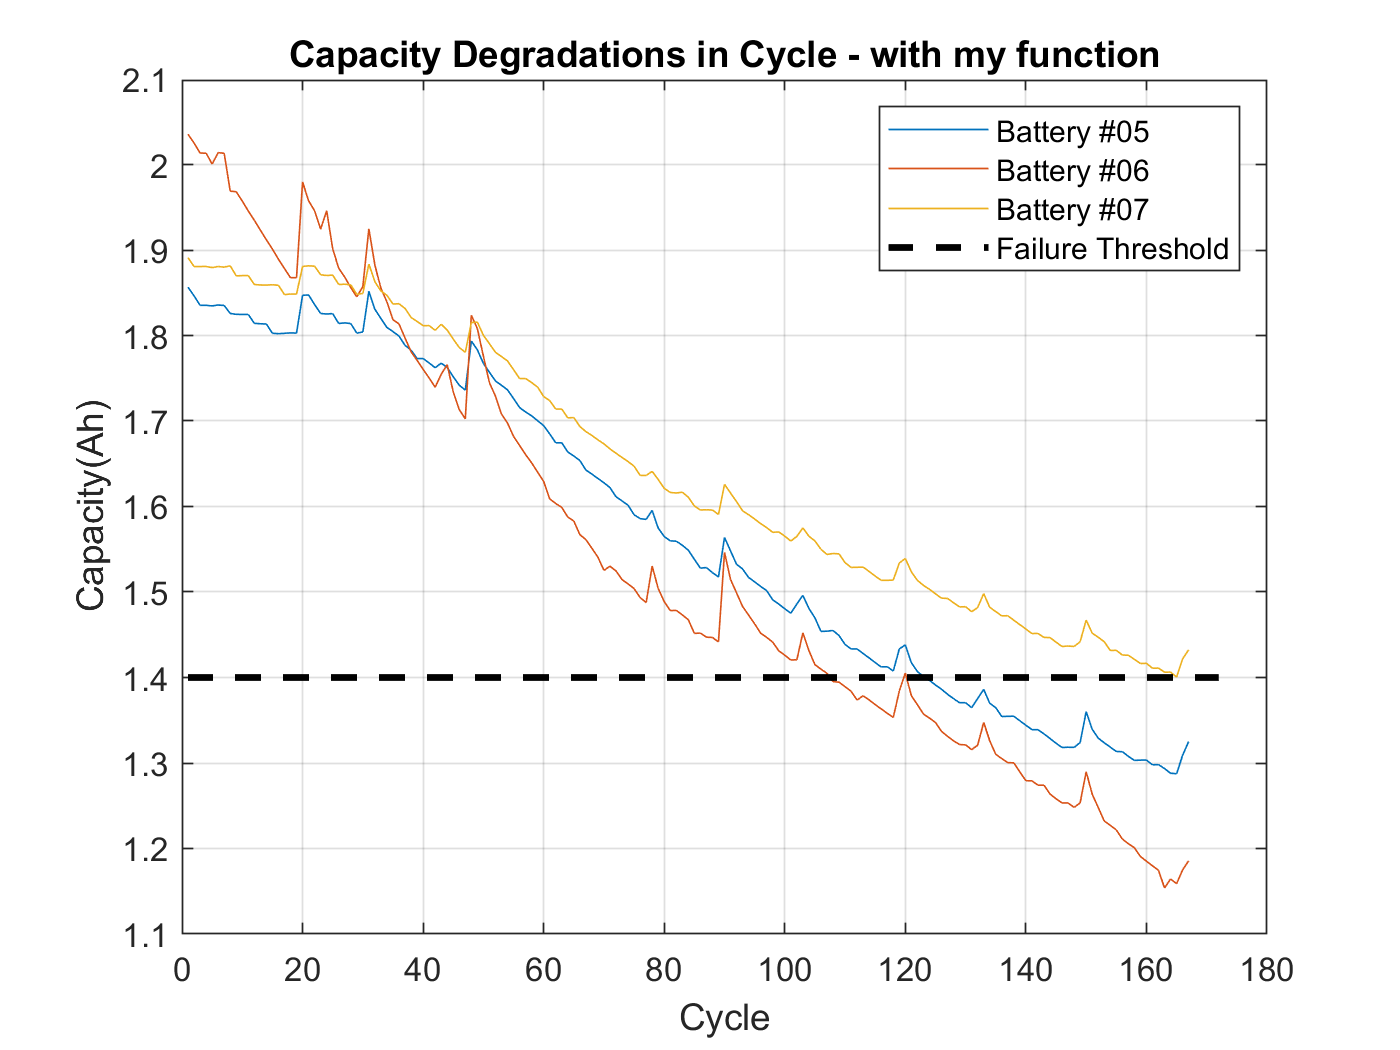

plot(cap_gen_05), hold on, plot(cap_gen_06), plot(cap_gen_07)
plot(1:len, 1.4*ones(1, len),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #05', 'Battery #06', 'Battery #07', 'Failure Threshold')
title('Capacity Degradations in Cycle - with my function')

len = length(cap_05) + 5

len = 97

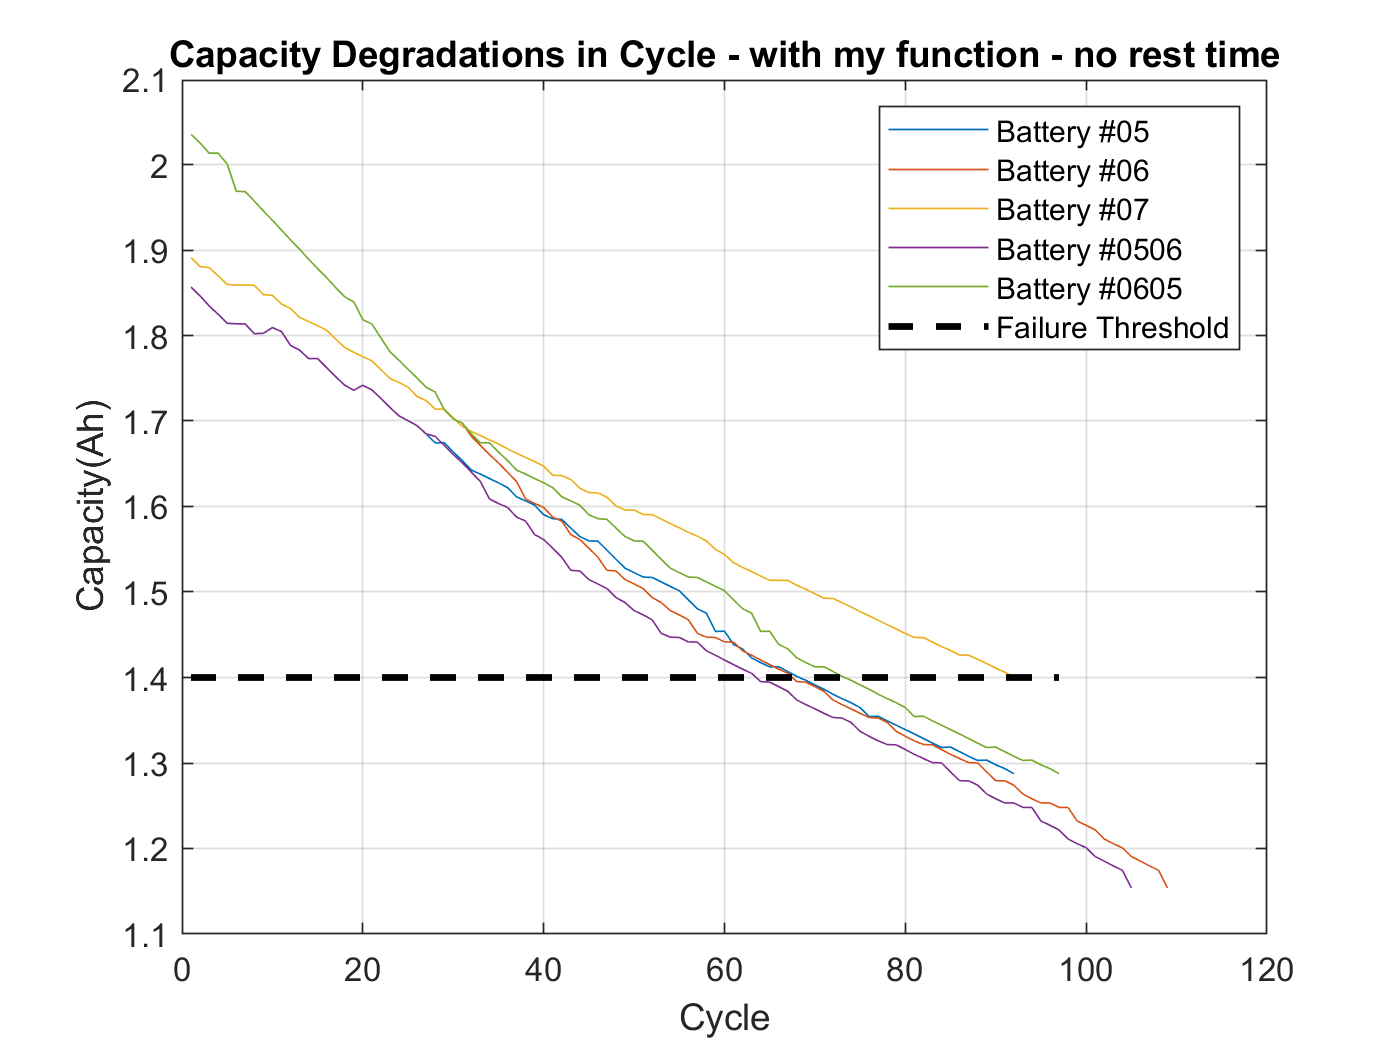

plot(cap_05), hold on, plot(cap_06), plot(cap_07), plot(cap_0506), plot(cap_0605)
plot(1:len, 1.4*ones(1, len),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #05', 'Battery #06', 'Battery #07', 'Battery #0506','Battery #0605','Failure Threshold')
title('Capacity Degradations in Cycle - with my function - no rest time')

len = length(cap_05plus06plus07) + 5

len = 298

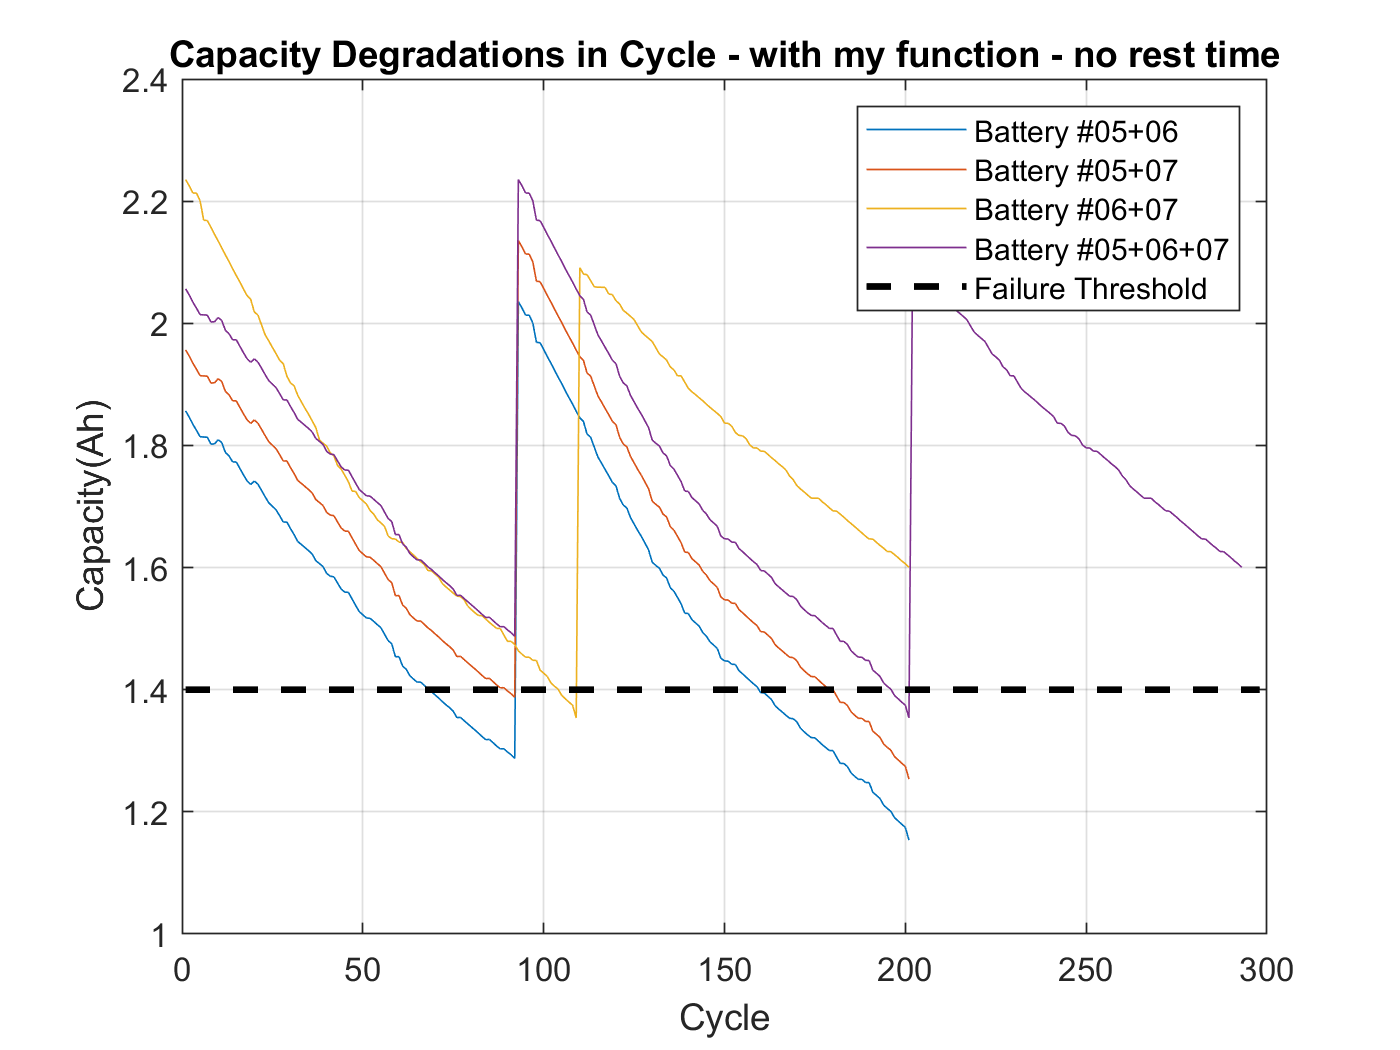

% add 0.1 to show graph more easily
plot(cap_05plus06), hold on, plot(cap_05plus07+0.1), plot(cap_06plus07+0.2), plot(cap_05plus06plus07+0.2)
plot(1:len, 1.4*ones(1, len),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #05+06', 'Battery #05+07', 'Battery #06+07', 'Battery #05+06+07','Failure Threshold')
title('Capacity Degradations in Cycle - with my function - no rest time')

reg_idx_cCcEndTimeSec = 1;
reg_idx_pattern_dVolt = 2;
reg_idx_capacity = 3;

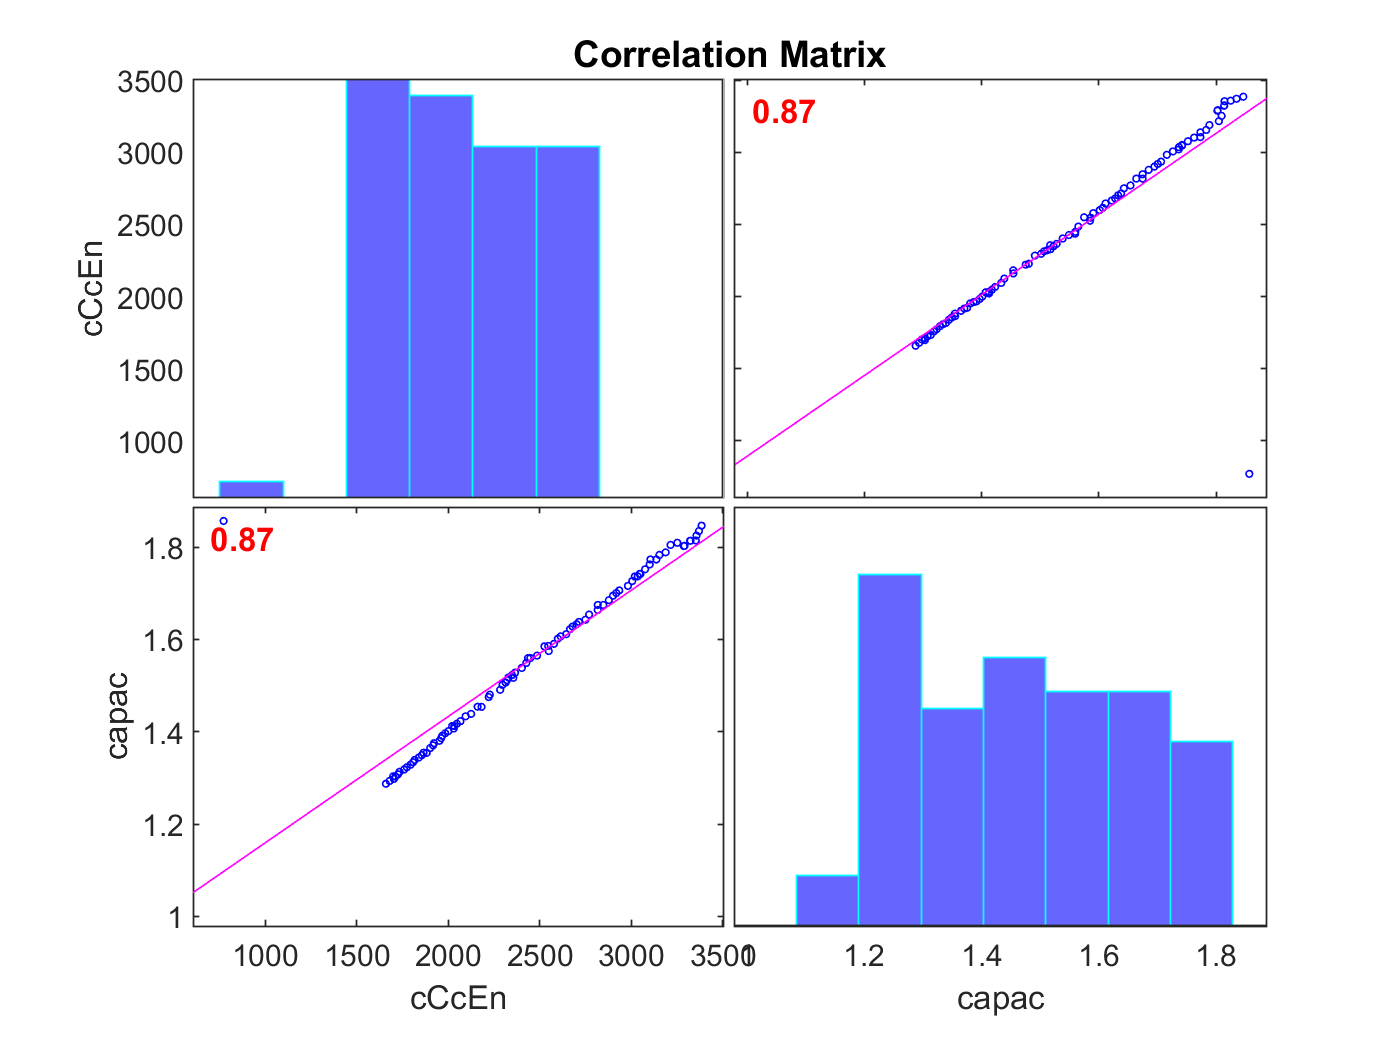

% error after adding pattern_dVolt
figure
corrplot(regression_vector_05(:,[reg_idx_cCcEndTimeSec reg_idx_capacity]),'type','Pearson','testR','on','varNames',{'cCcEndTimeSec','capacity'})

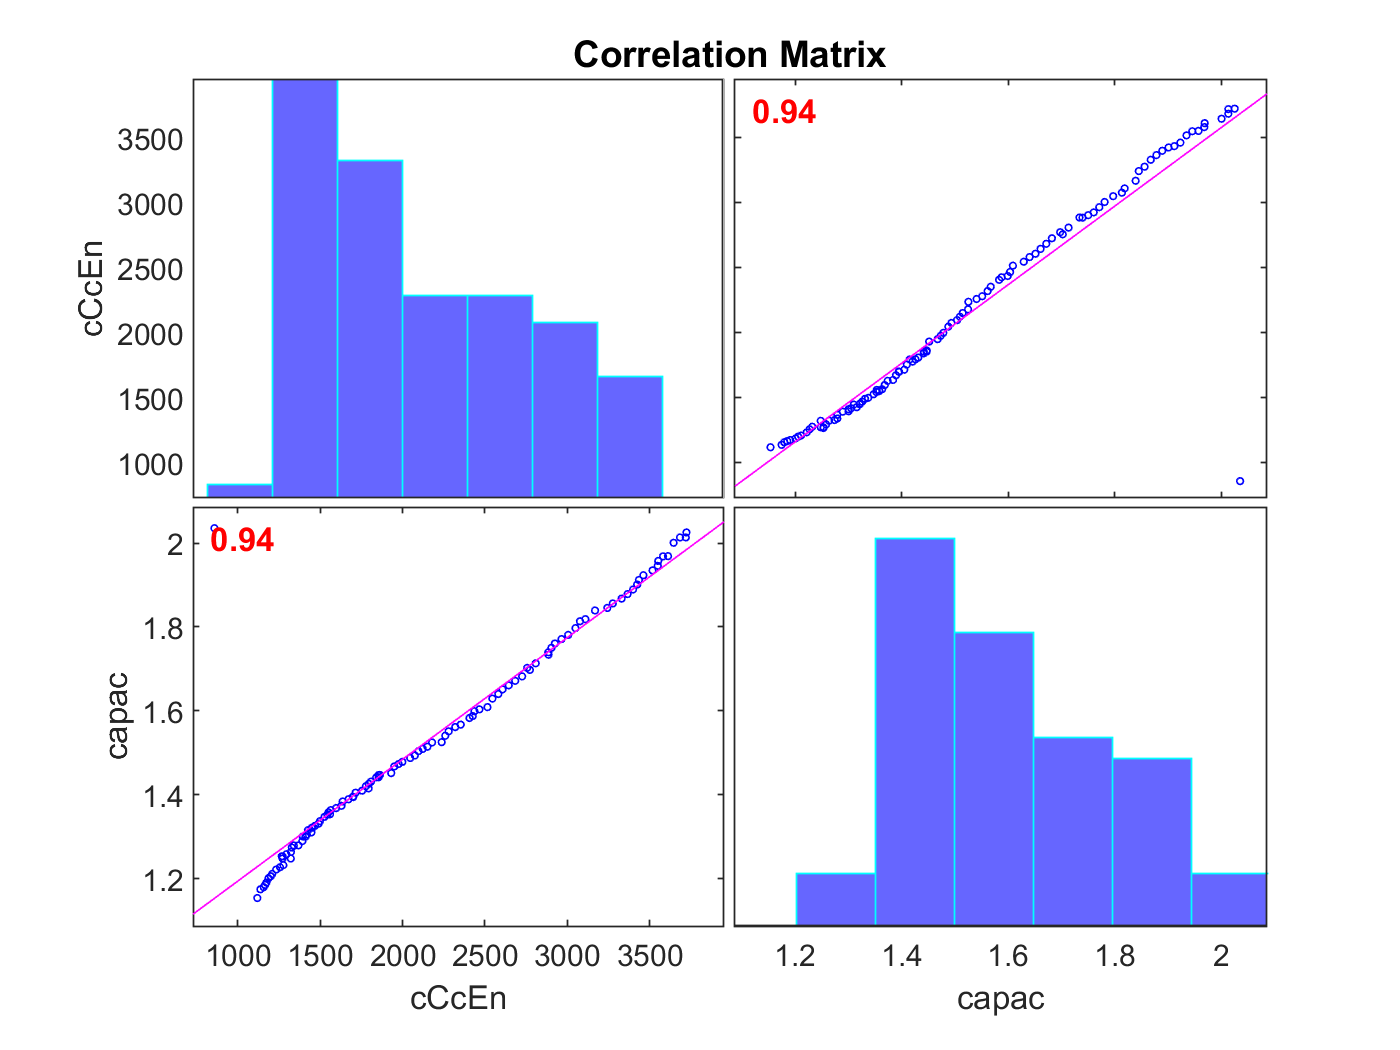

figure
corrplot(regression_vector_06(:,[reg_idx_cCcEndTimeSec reg_idx_capacity]),'type','Pearson','testR','on','varNames',{'cCcEndTimeSec','capacity'})

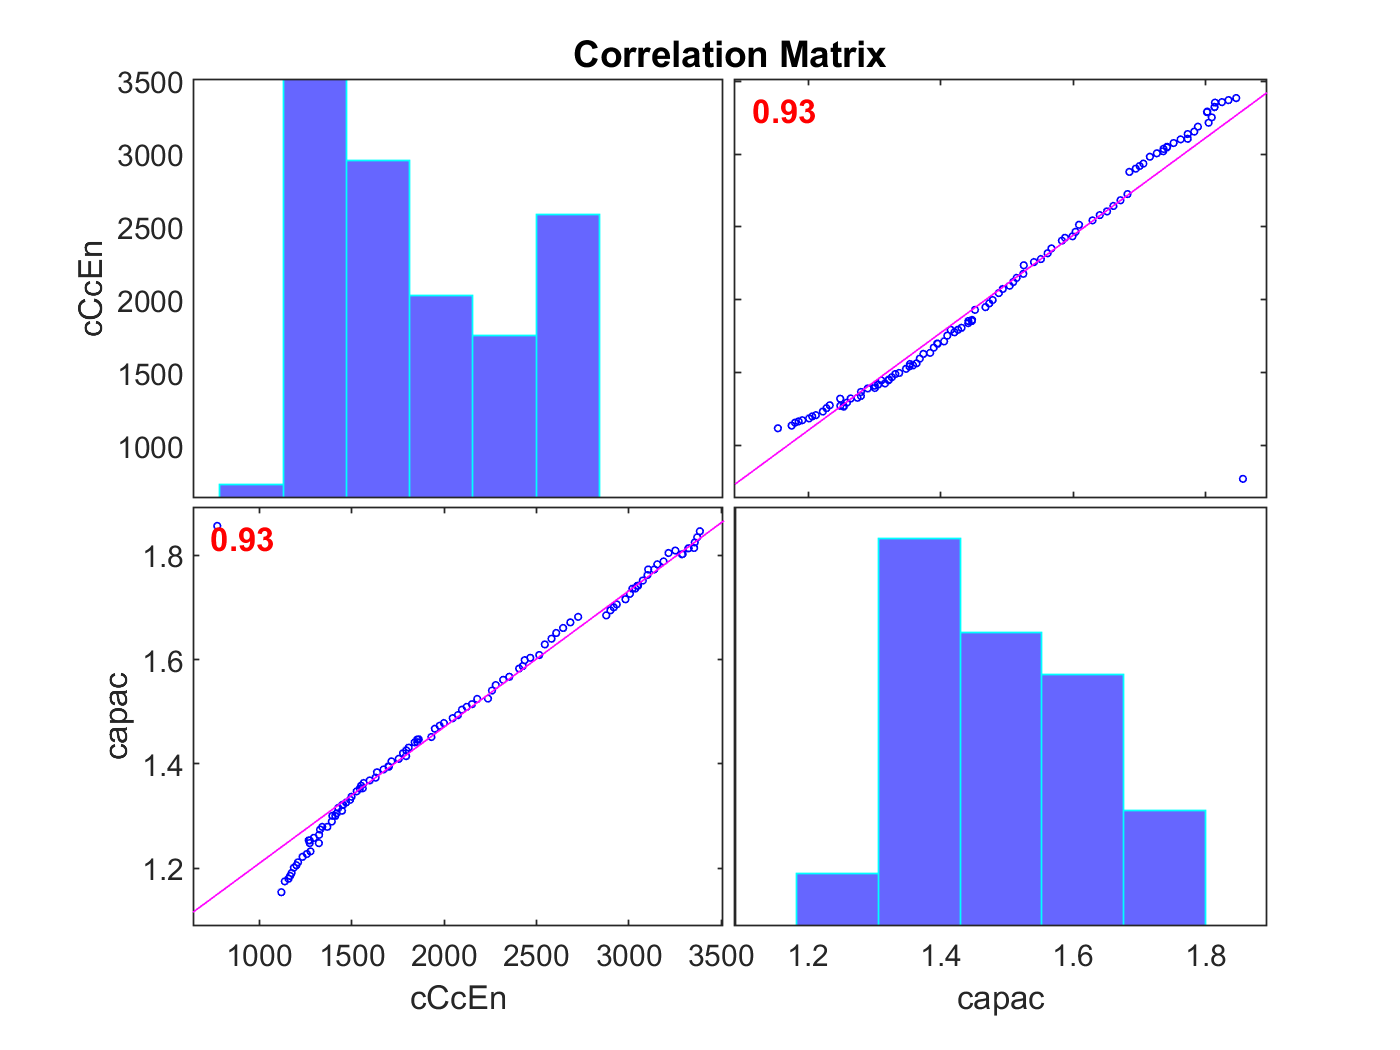

figure
corrplot(regression_vector_0506(:,[reg_idx_cCcEndTimeSec reg_idx_capacity]),'type','Pearson','testR','on','varNames',{'cCcEndTimeSec','capacity'})

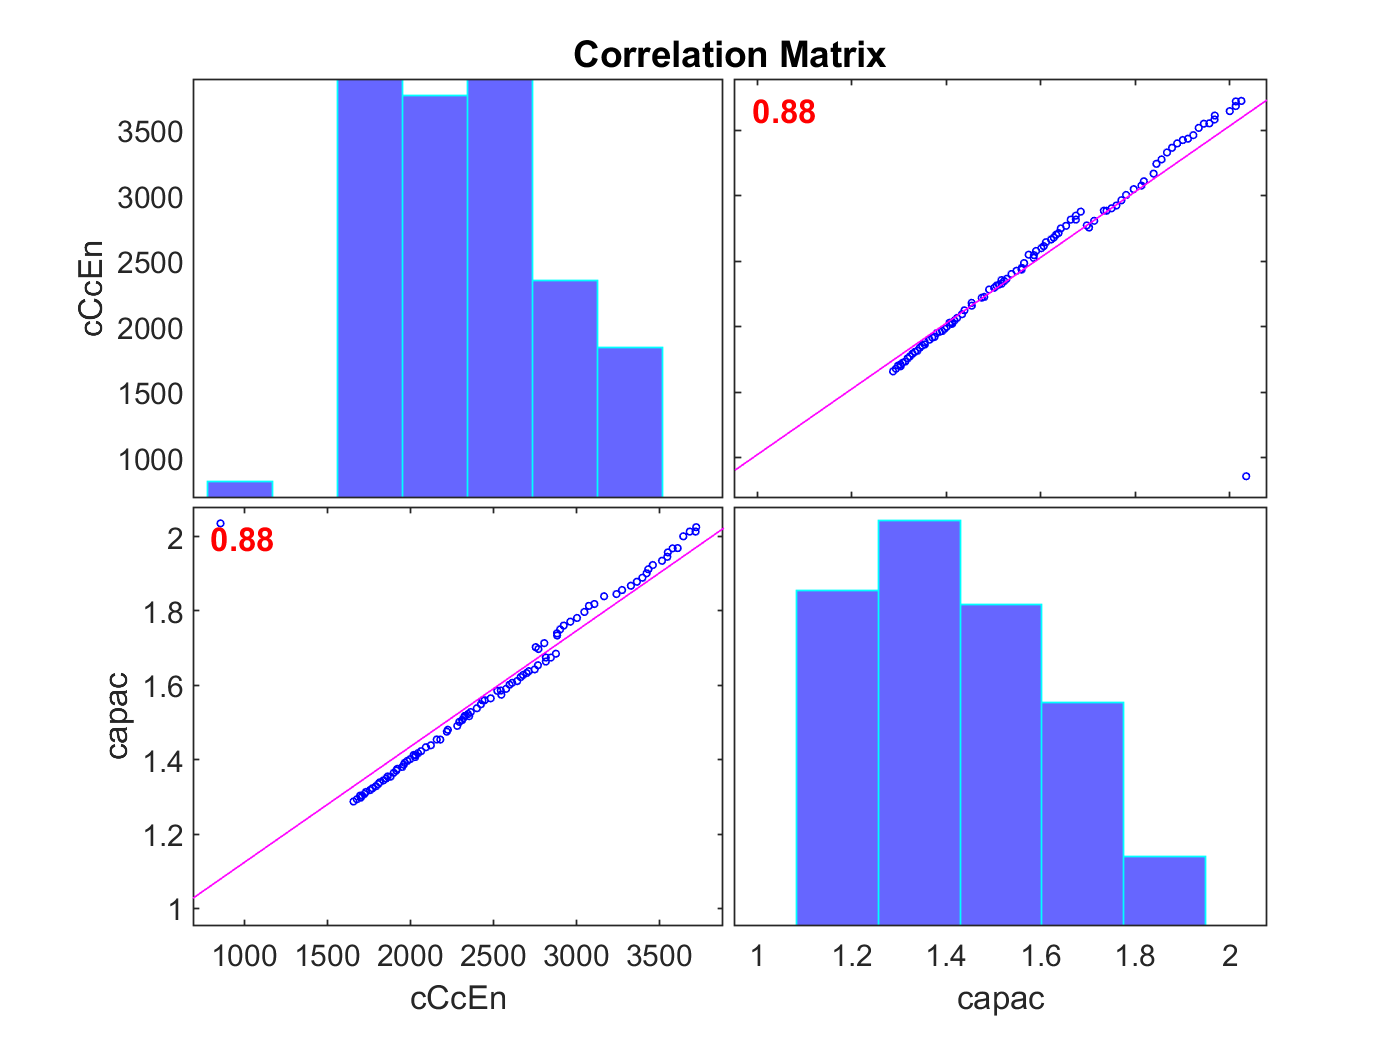

figure
corrplot(regression_vector_0605(:,[reg_idx_cCcEndTimeSec reg_idx_capacity]),'type','Pearson','testR','on','varNames',{'cCcEndTimeSec','capacity'})

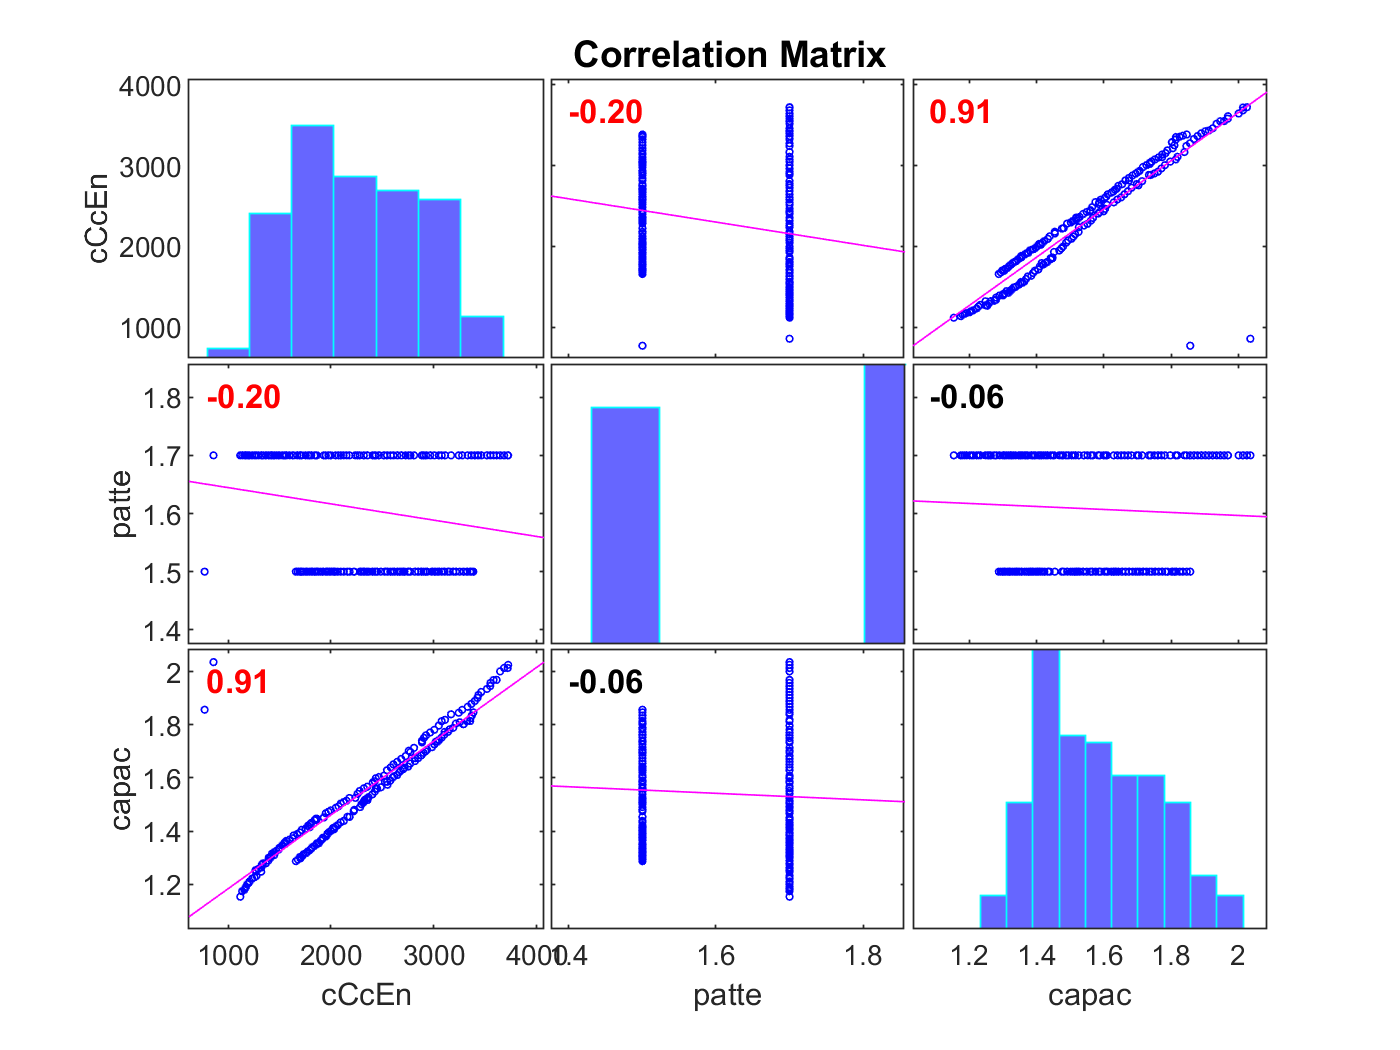

figure
corrplot(regression_vector_05plus06,'type','Pearson','testR','on','varNames',{'cCcEndTimeSec','pattern_dVolt','capacity'})

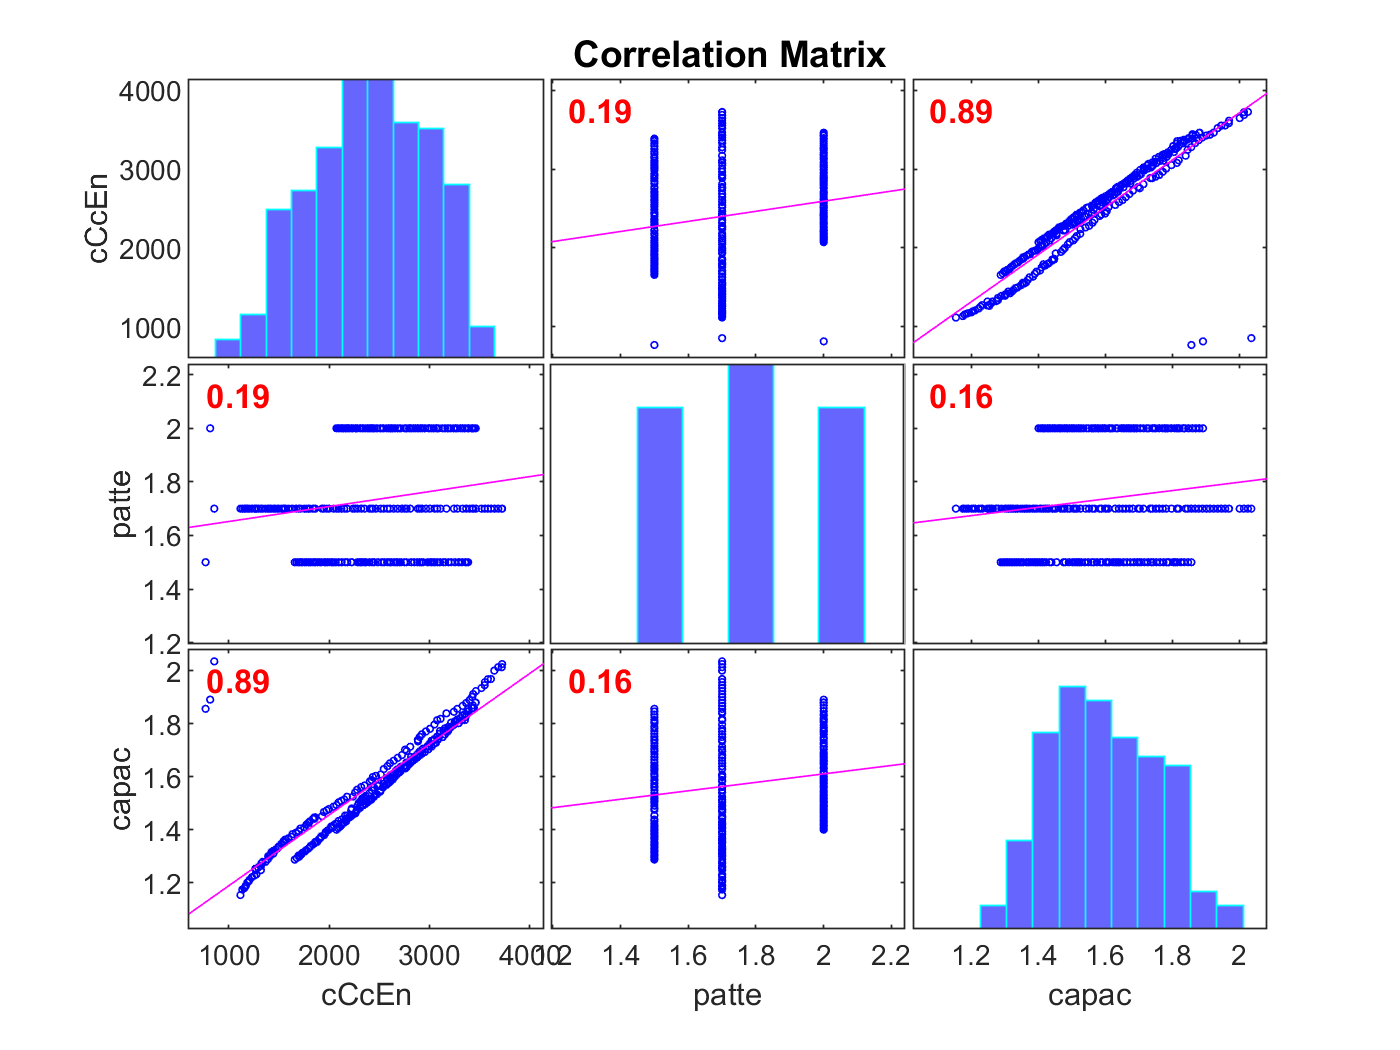

figure
corrplot(regression_vector_05plus06plus07,'type','Pearson','testR','on','varNames',{'cCcEndTimeSec','pattern_dVolt','capacity'})


%% linear regression

% https://kr.mathworks.com/help/stats/fitlm.html
modelspec_no_pattern = ' capacity ~  cCcEndTimeSec ';
modelspec_with_pattern = ' capacity ~  cCcEndTimeSec + pattern_dVolt ';

regression_table_all = B5,6

mdl_no_pattern_by_05plus06 = fitlm(regression_table_05plus06,modelspec_no_pattern )

mdl_no_pattern_by_05plus06 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec

Estimated Coefficients:
                      Estimate         SE        tStat       pValue   
                     __________    __________    ______    ___________

    (Intercept)         0.90669       0.02152    42.132    4.1829e-101
    cCcEndTimeSec    0.00027724    8.9733e-06    30.896     7.1667e-78


Number of observations: 201, Error degrees of freedom: 199
Root Mean Squared Error: 0.0909
R-squared: 0.827,  Adjusted R-Squared: 0.827
F-statistic vs. constant model: 955, p-value = 7.17e-78

mdl_with_pattern_by_05plus06 = fitlm(regression_table_05plus06,modelspec_with_pattern )

mdl_with_pattern_by_05plus06 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE        tStat       pValue  
                     __________    __________    ______    __________

    (Intercept)         0.42622       0.10672    3.9939    9.1593e-05
    cCcEndTimeSec    0.00028527    8.7303e-06    32.676    1.0644e-81
    pattern_dVolt       0.28728      0.062619    4.5878    7.9402e-06


Number of observations: 201, Error degrees of freedom: 198
Root Mean Squared Error: 0.0867
R-squared: 0.844,  Adjusted R-Squared: 0.842
F-statistic vs. constant model: 536, p-value = 1.26e-80


mdl_with_pattern_by_05 = fitlm(regression_table_05,modelspec_with_pattern )

mdl_with_pattern_by_05 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE        tStat       pValue  
                     __________    __________    ______    __________

    (Intercept)               0             0       NaN           NaN
    cCcEndTimeSec    0.00027318    1.5981e-05    17.094    7.3903e-30
    pattern_dVolt       0.44336      0.020036    22.128    6.0591e-38


Number of observations: 92, Error degrees of freedom: 90
Root Mean Squared Error: 0.0851
R-squared: 0.765,  Adjusted R-Squared: 0.762
F-statistic vs. constant model: 292, p-value = 5.23e-30

mdl_no_pattern_by_05 = fitlm(regression_table_05,modelspec_no_pattern )

mdl_no_pattern_by_05 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec

Estimated Coefficients:
                      Estimate         SE        tStat       pValue  
                     __________    __________    ______    __________

    (Intercept)         0.88672      0.040073    22.128    3.6181e-38
    cCcEndTimeSec    0.00027318    1.5981e-05    17.094    5.2252e-30


Number of observations: 92, Error degrees of freedom: 90
Root Mean Squared Error: 0.0851
R-squared: 0.765,  Adjusted R-Squared: 0.762
F-statistic vs. constant model: 292, p-value = 5.23e-30

mdl_with_pattern_by_06 = fitlm(regression_table_06,modelspec_with_pattern )

mdl_with_pattern_by_06 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + pattern_dVolt

Estimated Coefficients:
                      Estimate        SE        tStat       pValue  
                     __________    _________    ______    __________

    (Intercept)               0            0       NaN           NaN
    cCcEndTimeSec    0.00029016    1.051e-05    27.609    3.2234e-50
    pattern_dVolt       0.53179     0.014231    37.369    7.4947e-63


Number of observations: 109, Error degrees of freedom: 107
Root Mean Squared Error: 0.088
R-squared: 0.877,  Adjusted R-Squared: 0.876
F-statistic vs. constant model: 762, p-value = 1.74e-50

mdl_no_pattern_by_06 = fitlm(regression_table_06,modelspec_no_pattern )

mdl_no_pattern_by_06 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec

Estimated Coefficients:
                      Estimate        SE        tStat      pValue  
                     __________    _________    ______    _________

    (Intercept)         0.90405     0.024192    37.369    3.161e-63
    cCcEndTimeSec    0.00029016    1.051e-05    27.609    1.743e-50


Number of observations: 109, Error degrees of freedom: 107
Root Mean Squared Error: 0.088
R-squared: 0.877,  Adjusted R-Squared: 0.876
F-statistic vs. constant model: 762, p-value = 1.74e-50

mdl_with_pattern_by_0506 = fitlm(regression_table_0506,modelspec_with_pattern )

mdl_with_pattern_by_0506 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + pattern_dVolt

Estimated Coefficients:
                     Estimate         SE         tStat       pValue  
                     _________    __________    _______    __________

    (Intercept)         1.7539       0.22962     7.6382    1.2308e-11
    cCcEndTimeSec    0.0002206    1.4811e-05     14.895    2.4399e-27
    pattern_dVolt     -0.43731       0.12415    -3.5225    0.00064109


Number of observations: 105, Error degrees of freedom: 102
Root Mean Squared Error: 0.0698
R-squared: 0.887,  Adjusted R-Squared: 0.885
F-statistic vs. constant model: 400, p-value = 5.03e-49

mdl_no_pattern_by_0506 = fitlm(regression_table_0506,modelspec_no_pattern )

mdl_no_pattern_by_0506 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec

Estimated Coefficients:
                     Estimate         SE        tStat       pValue  
                     _________    __________    ______    __________

    (Intercept)        0.94832      0.021669    43.764    2.2919e-68
    cCcEndTimeSec    0.0002612    9.8036e-06    26.643    5.2317e-48


Number of observations: 105, Error degrees of freedom: 103
Root Mean Squared Error: 0.0736
R-squared: 0.873,  Adjusted R-Squared: 0.872
F-statistic vs. constant model: 710, p-value = 5.23e-48

mdl_with_pattern_by_0605 = fitlm(regression_table_0605,modelspec_with_pattern )

mdl_with_pattern_by_0605 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE         tStat       pValue  
                     __________    __________    _______    __________

    (Intercept)        -0.49935       0.17092    -2.9216      0.004361
    cCcEndTimeSec    0.00019795    1.9606e-05     10.096    1.1479e-16
    pattern_dVolt        1.0208       0.13033     7.8324    7.1629e-12


Number of observations: 97, Error degrees of freedom: 94
Root Mean Squared Error: 0.0808
R-squared: 0.867,  Adjusted R-Squared: 0.864
F-statistic vs. constant model: 307, p-value = 6.04e-42

mdl_no_pattern_by_0605 = fitlm(regression_table_0605,modelspec_no_pattern )

mdl_no_pattern_by_0605 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec

Estimated Coefficients:
                      Estimate         SE        tStat       pValue  
                     __________    __________    ______    __________

    (Intercept)         0.81211      0.043865    18.514    2.7979e-33
    cCcEndTimeSec    0.00031123    1.6927e-05    18.386    4.6836e-33


Number of observations: 97, Error degrees of freedom: 95
Root Mean Squared Error: 0.103
R-squared: 0.781,  Adjusted R-Squared: 0.778
F-statistic vs. constant model: 338, p-value = 4.68e-33

## Save model

% mdl_with_pattern_by_05plus06
% mdl_with_pattern_by_05
% mdl_with_pattern_by_06
% mdl_with_pattern_by_0506
% mdl_with_pattern_by_0605

여기까재

%% get  hat 
% https://kr.mathworks.com/help/macapacityX1U1Hat6tlab/matlab_prog/access-data-in-a-table.html

% self
capHat_05plus06_with_pattern_by_05plus06 = predict(mdl_with_pattern_by_05plus06,regression_table_05plus06(:,{'cCcEndTimeSec','pattern_dVolt'}))';
capHat_05_with_pattern_by_05 = predict(mdl_with_pattern_by_05,regression_table_05(:,{'cCcEndTimeSec','pattern_dVolt'}))';
capHat_06_with_pattern_by_06 = predict(mdl_with_pattern_by_06,regression_table_06(:,{'cCcEndTimeSec','pattern_dVolt'}))';
capHat_0506_with_pattern_by_0506 = predict(mdl_with_pattern_by_0506,regression_table_0506(:,{'cCcEndTimeSec','pattern_dVolt'}))';
capHat_0605_with_pattern_by_0605 = predict(mdl_with_pattern_by_0605,regression_table_0605(:,{'cCcEndTimeSec','pattern_dVolt'}))';

% by all
capHat_05_with_pattern_by_05plus06 = predict(mdl_with_pattern_by_05plus06,regression_table_05(:,{'cCcEndTimeSec','pattern_dVolt'}))';
capHat_06_with_pattern_by_05plus06 = predict(mdl_with_pattern_by_05plus06,regression_table_06(:,{'cCcEndTimeSec','pattern_dVolt'}))';
capHat_0506_with_pattern_by_05plus06 = predict(mdl_with_pattern_by_05plus06,regression_table_0506(:,{'cCcEndTimeSec','pattern_dVolt'}))';
capHat_0605_with_pattern_by_05plus06 = predict(mdl_with_pattern_by_05plus06,regression_table_0605(:,{'cCcEndTimeSec','pattern_dVolt'}))';

% by 5
capHat_05plus06_with_pattern_by_05 = predict(mdl_with_pattern_by_05,regression_table_05plus06(:,{'cCcEndTimeSec','pattern_dVolt'}))';
capHat_06_with_pattern_by_05   = predict(mdl_with_pattern_by_05,regression_table_06(:,{'cCcEndTimeSec','pattern_dVolt'}))';
capHat_0506_with_pattern_by_05 = predict(mdl_with_pattern_by_05,regression_table_0506(:,{'cCcEndTimeSec','pattern_dVolt'}))';
capHat_0605_with_pattern_by_05 = predict(mdl_with_pattern_by_05,regression_table_0605(:,{'cCcEndTimeSec','pattern_dVolt'}))';

% by 6
capHat_05plus06_with_pattern_by_06 = predict(mdl_with_pattern_by_06,regression_table_05plus06(:,{'cCcEndTimeSec','pattern_dVolt'}))';
capHat_05_with_pattern_by_06   = predict(mdl_with_pattern_by_06,regression_table_05(:,{'cCcEndTimeSec','pattern_dVolt'}))';
capHat_0506_with_pattern_by_06 = predict(mdl_with_pattern_by_06,regression_table_0506(:,{'cCcEndTimeSec','pattern_dVolt'}))';
capHat_0605_with_pattern_by_06 = predict(mdl_with_pattern_by_06,regression_table_0605(:,{'cCcEndTimeSec','pattern_dVolt'}))';

% by 56
capHat_05plus06_with_pattern_by_0506 = predict(mdl_with_pattern_by_0506,regression_table_05plus06(:,{'cCcEndTimeSec','pattern_dVolt'}))';
capHat_05_with_pattern_by_0506   = predict(mdl_with_pattern_by_0506,regression_table_05(:,{'cCcEndTimeSec','pattern_dVolt'}))';
capHat_06_with_pattern_by_0506 = predict(mdl_with_pattern_by_0506,regression_table_06(:,{'cCcEndTimeSec','pattern_dVolt'}))';
capHat_0605_with_pattern_by_0506 = predict(mdl_with_pattern_by_0506,regression_table_0605(:,{'cCcEndTimeSec','pattern_dVolt'}))';

% by 65
capHat_05plus06_with_pattern_by_0605 = predict(mdl_with_pattern_by_0605,regression_table_05plus06(:,{'cCcEndTimeSec','pattern_dVolt'}))';
capHat_05_with_pattern_by_0605   = predict(mdl_with_pattern_by_0605,regression_table_05(:,{'cCcEndTimeSec','pattern_dVolt'}))';
capHat_06_with_pattern_by_0605 = predict(mdl_with_pattern_by_0605,regression_table_06(:,{'cCcEndTimeSec','pattern_dVolt'}))';
capHat_0506_with_pattern_by_0605 = predict(mdl_with_pattern_by_0605,regression_table_0506(:,{'cCcEndTimeSec','pattern_dVolt'}))';


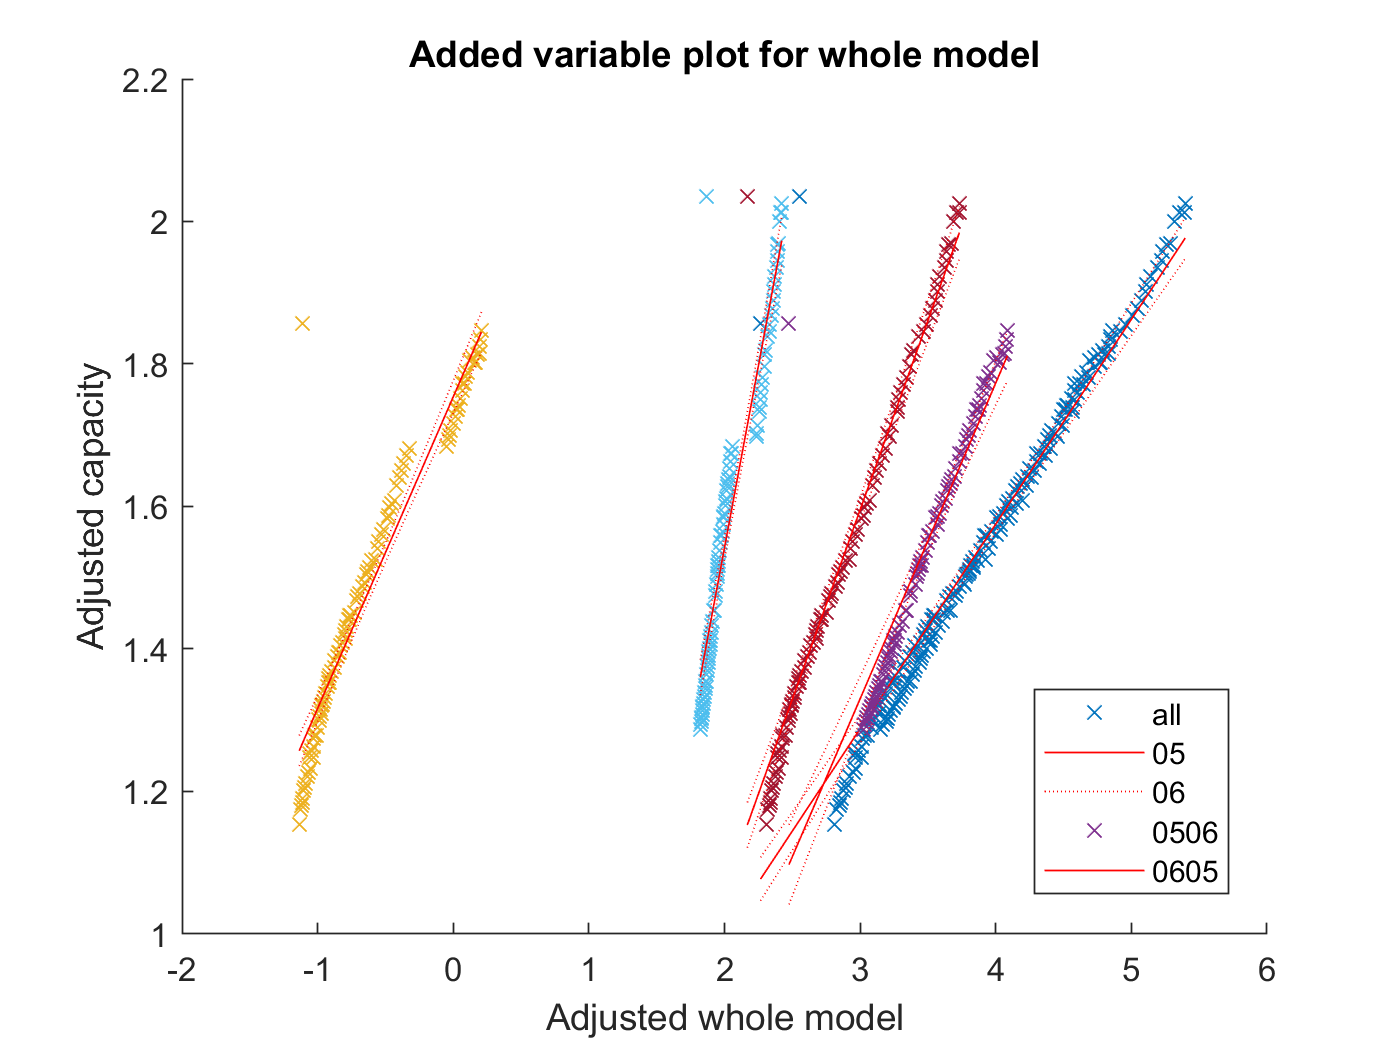


%% plot - model
figure
hold on 
plot(mdl_with_pattern_by_05plus06)
plot(mdl_with_pattern_by_05)
plot(mdl_with_pattern_by_06)
plot(mdl_with_pattern_by_0506)
plot(mdl_with_pattern_by_0605)
hold off
legend('all','05','06','0506','0605')

## plot - residuals

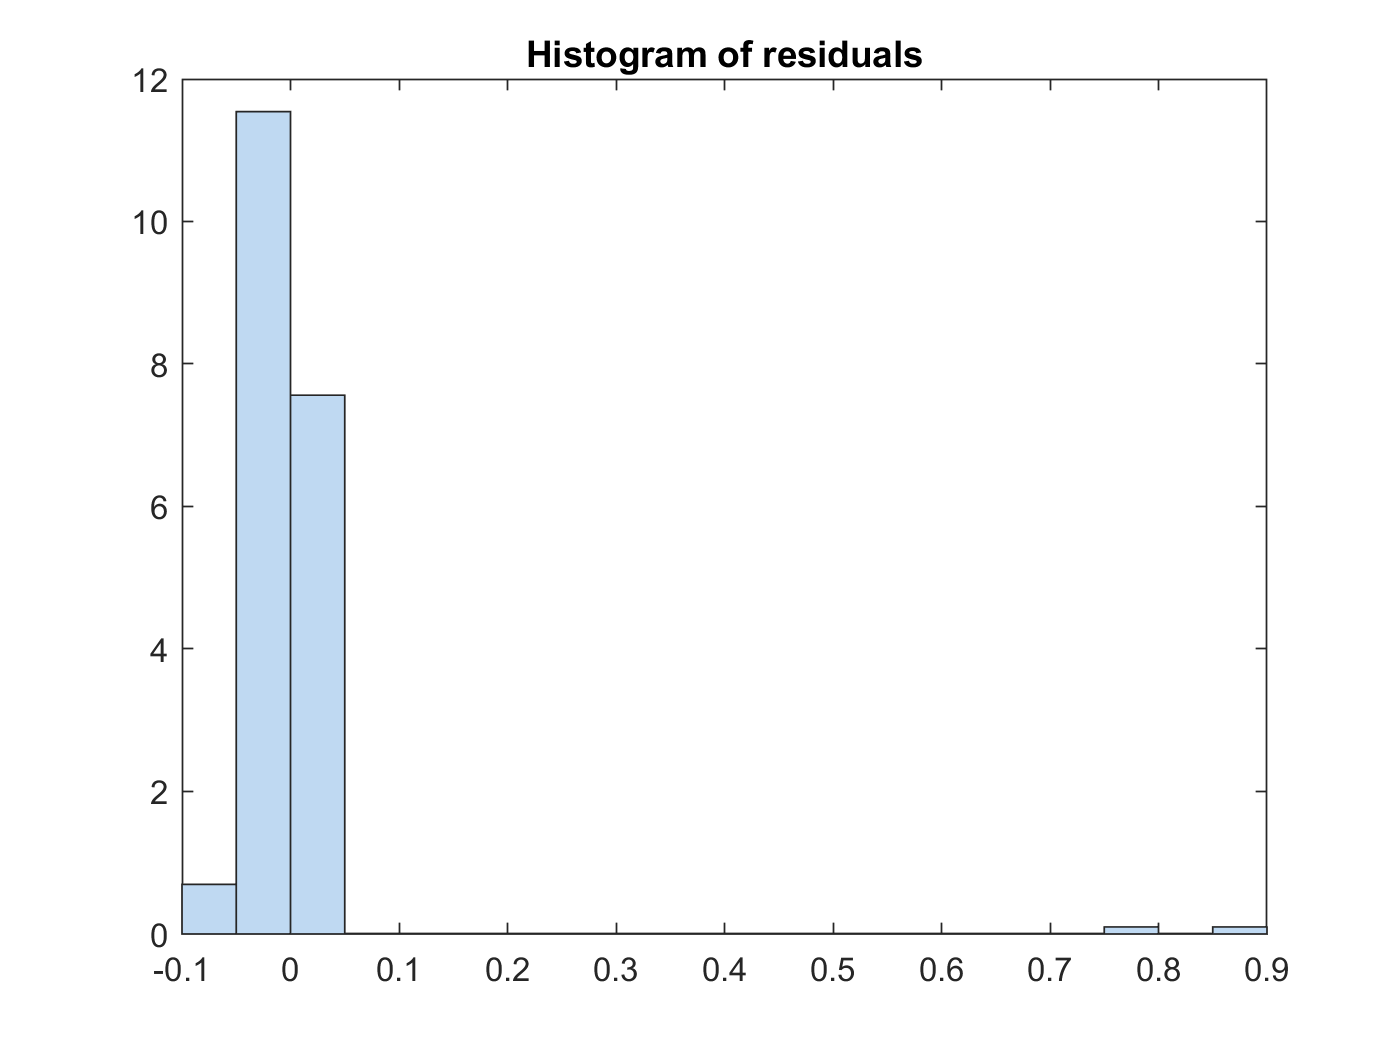

plotResiduals(mdl_with_pattern_by_05plus06)

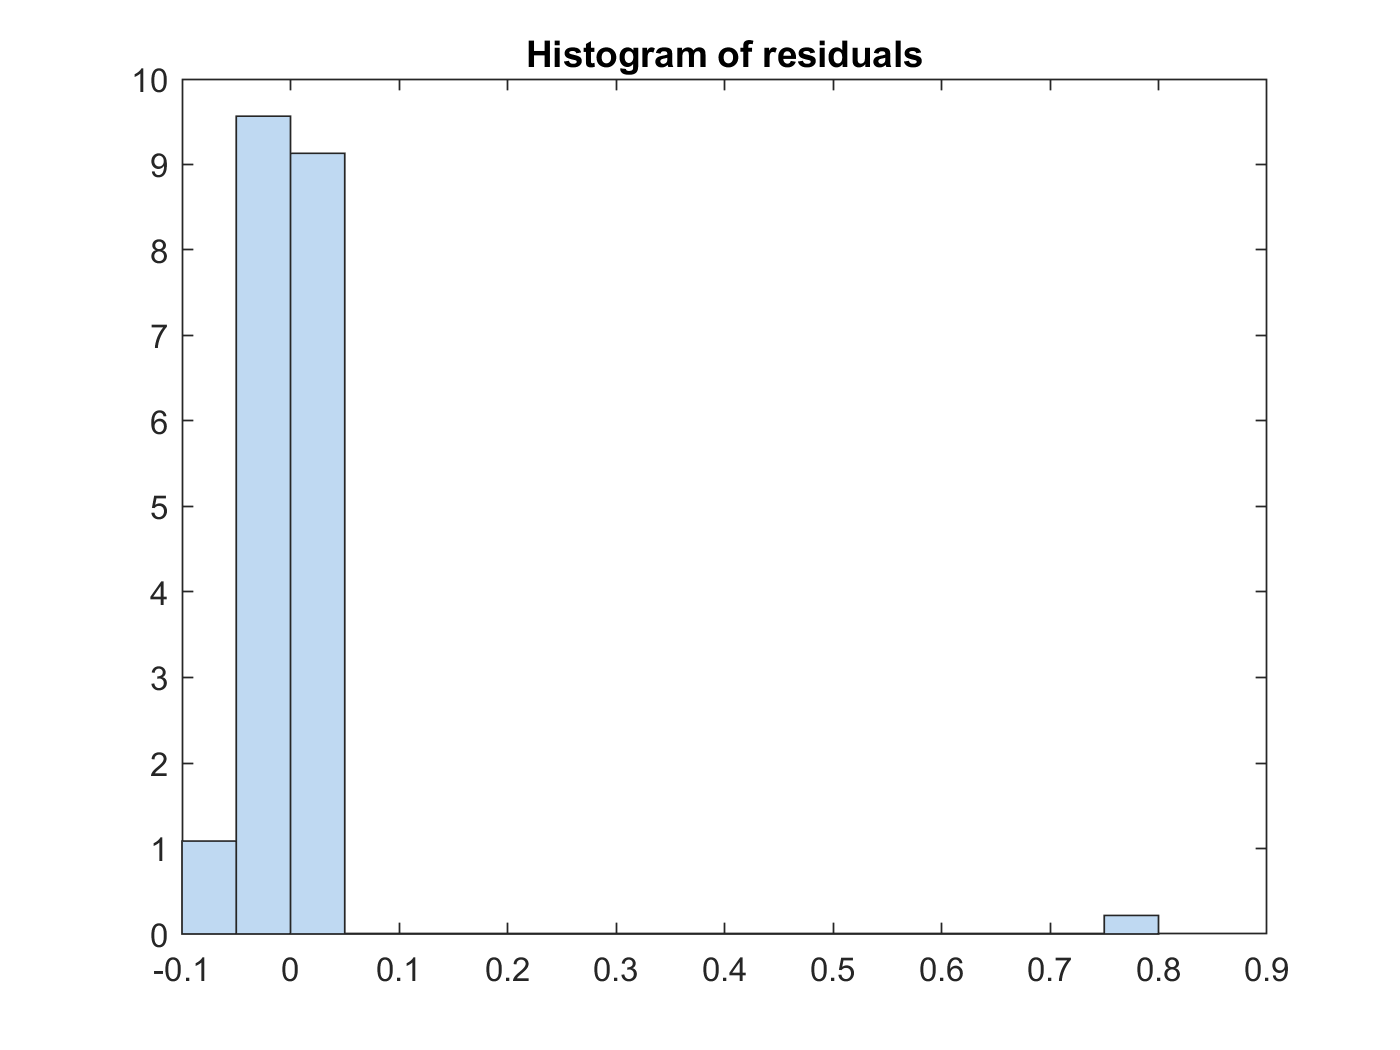

plotResiduals(mdl_with_pattern_by_05)

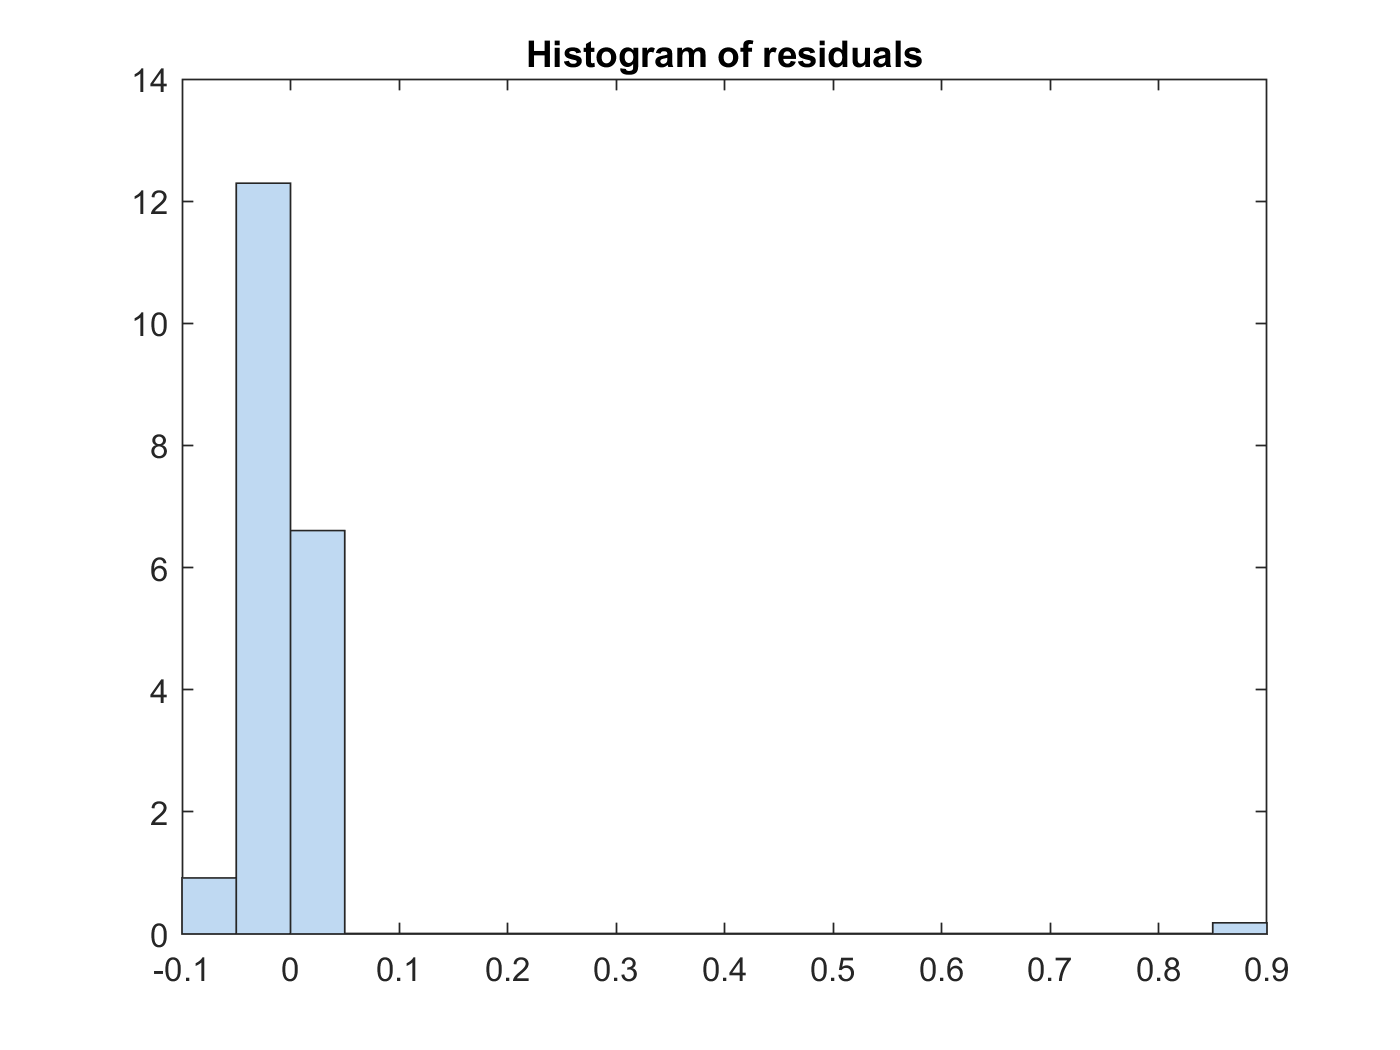

plotResiduals(mdl_with_pattern_by_06)

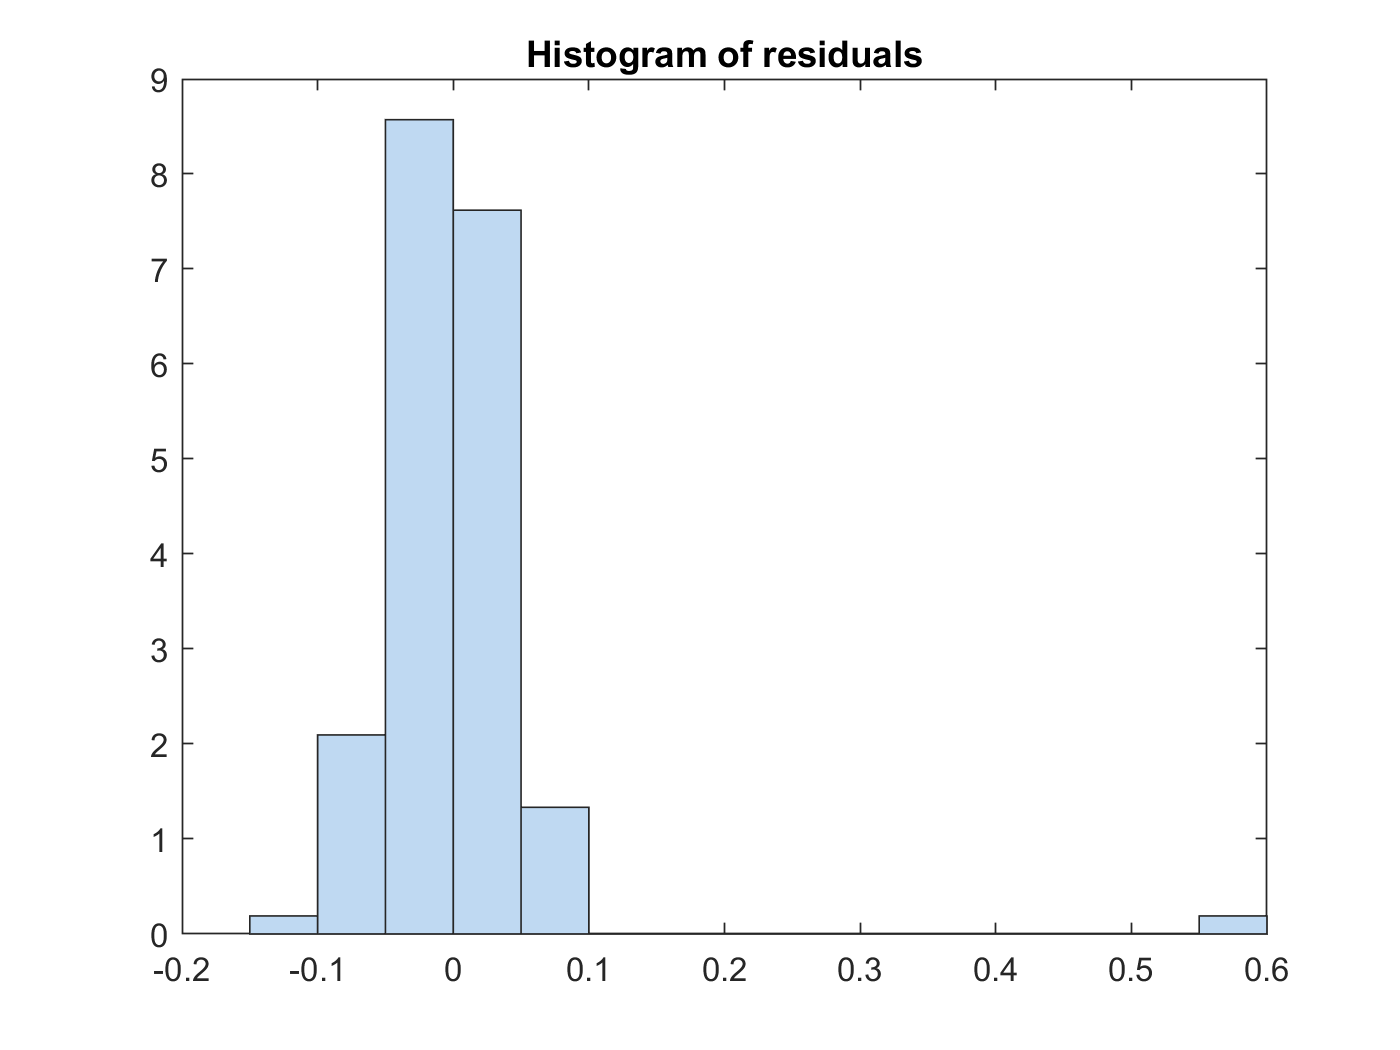

plotResiduals(mdl_with_pattern_by_0506)

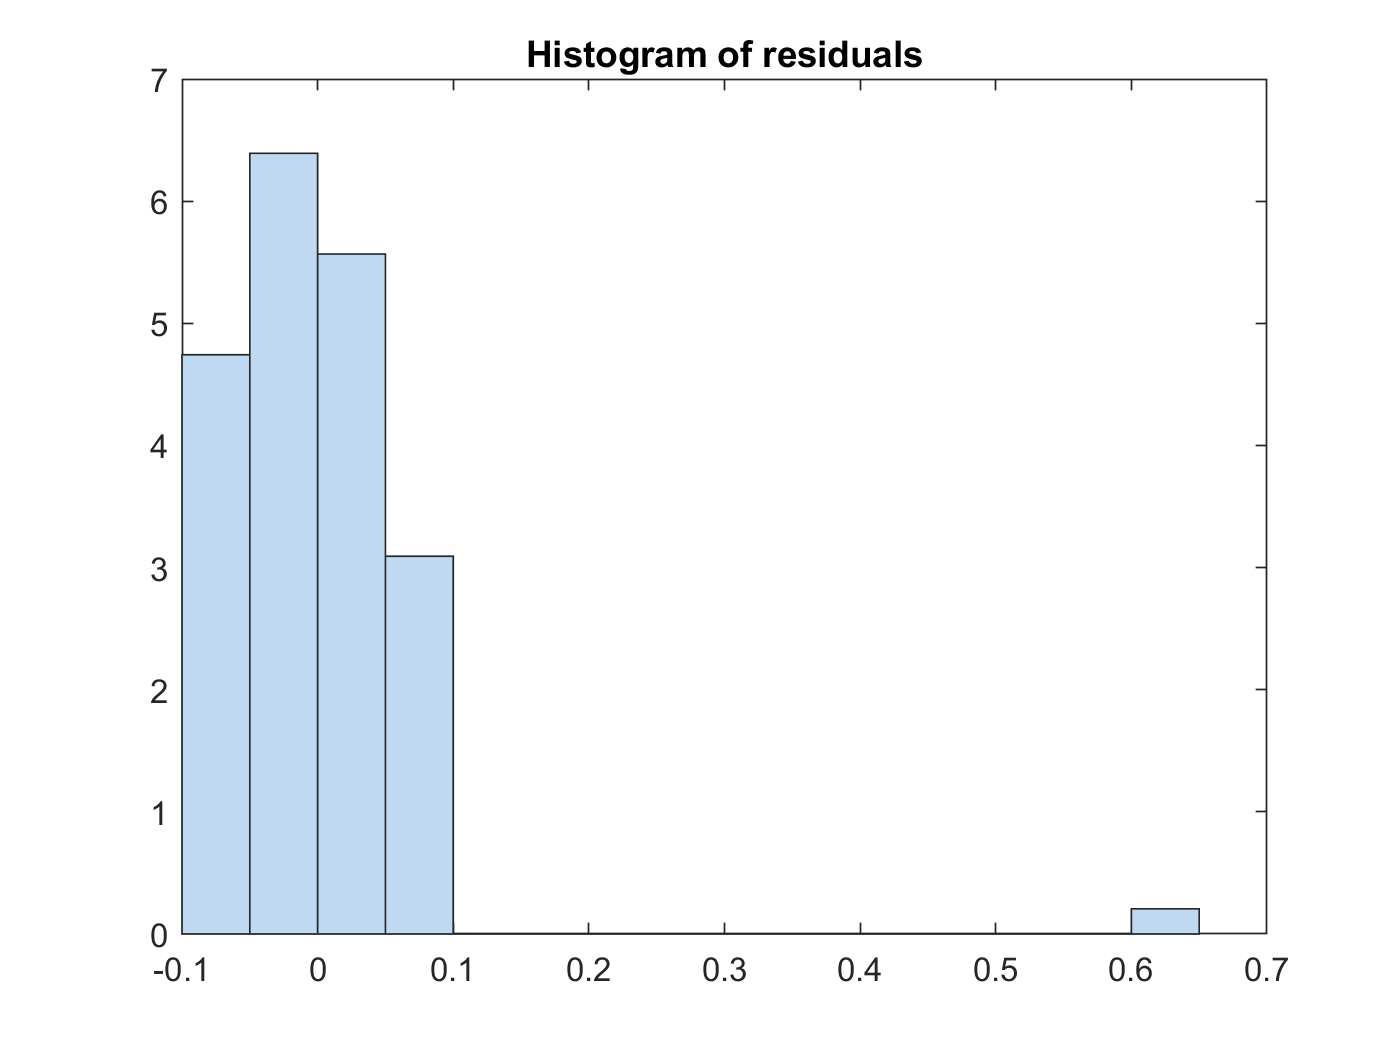

plotResiduals(mdl_with_pattern_by_0605)

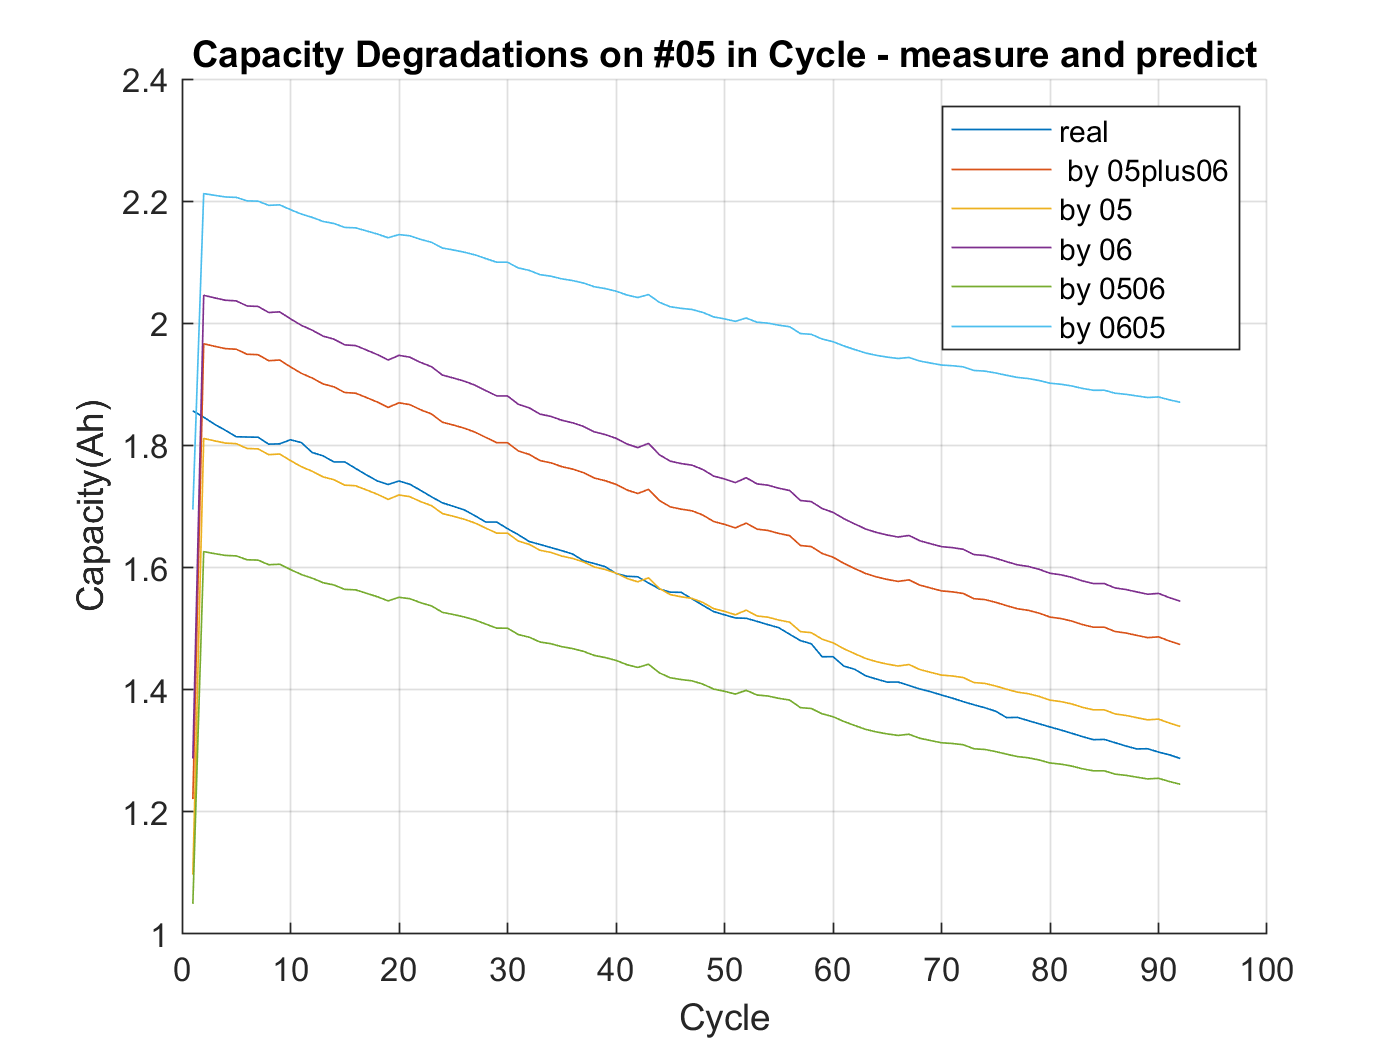


%% plot - hat #5 
figure, hold on,xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations on #05 in Cycle - measure and predict')
plot(cap_05), plot(capHat_05_with_pattern_by_05plus06),plot(capHat_05_with_pattern_by_05),plot(capHat_05_with_pattern_by_06),plot(capHat_05_with_pattern_by_0506),plot(capHat_05_with_pattern_by_0605),
hold off, grid on, legend('real',' by 05plus06','by 05','by 06','by 0506','by 0605')

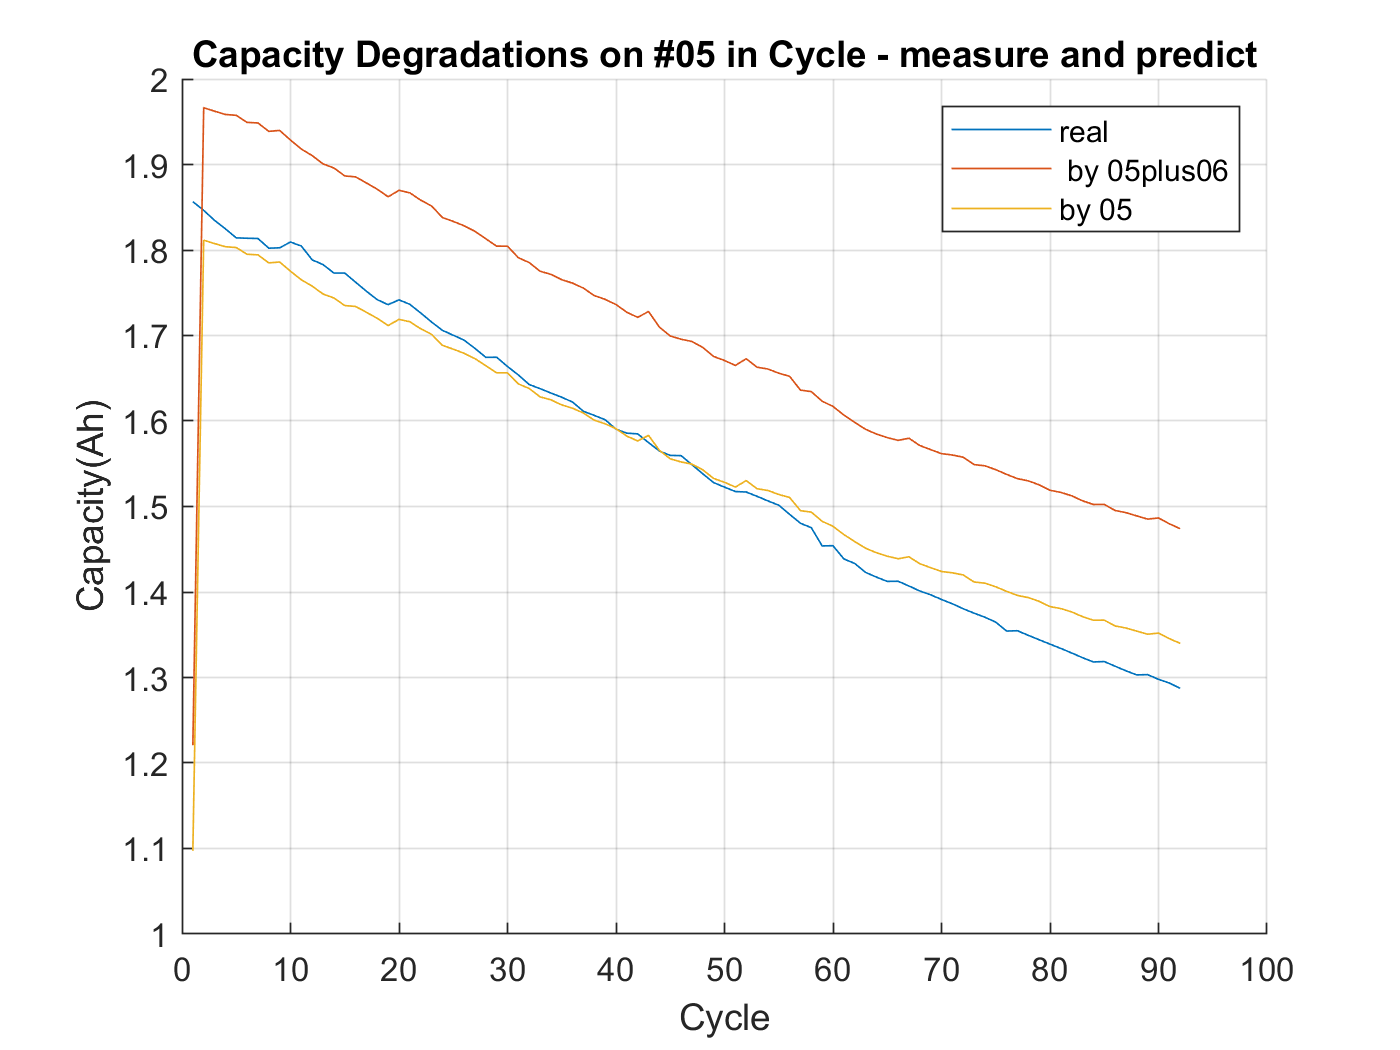

%% plot - hat #5 
figure, hold on,xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations on #05 in Cycle - measure and predict')
plot(cap_05), plot(capHat_05_with_pattern_by_05plus06),plot(capHat_05_with_pattern_by_05)
hold off, grid on, legend('real',' by 05plus06','by 05')

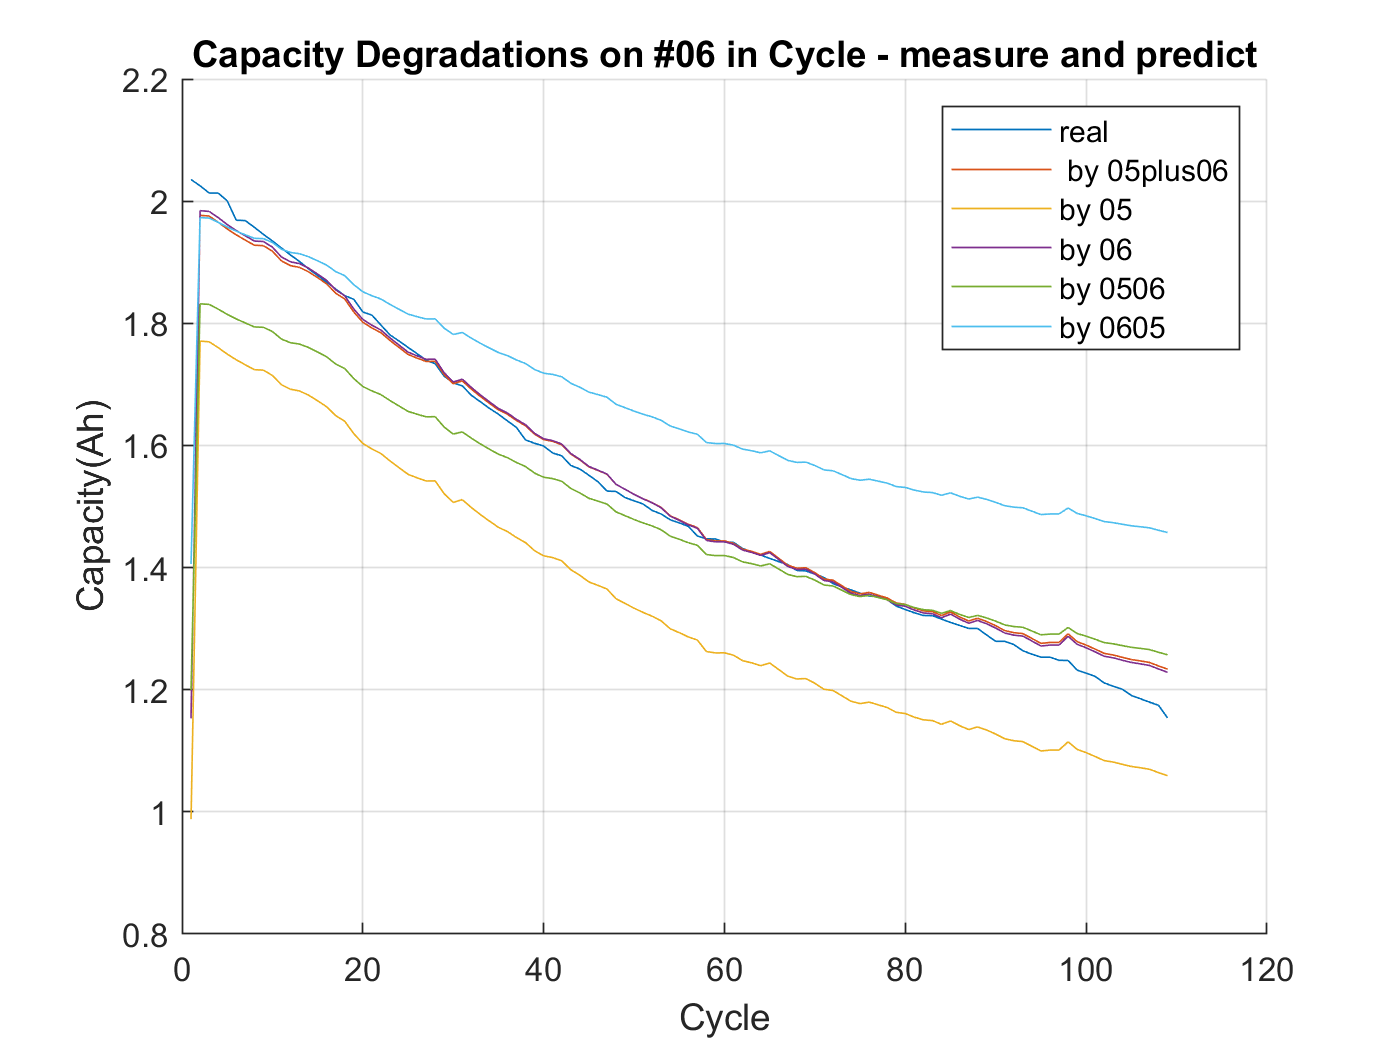


%% plot - hat #6 
figure, hold on,xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations on #06 in Cycle - measure and predict')
plot(cap_06), plot(capHat_06_with_pattern_by_05plus06),plot(capHat_06_with_pattern_by_05),plot(capHat_06_with_pattern_by_06),plot(capHat_06_with_pattern_by_0506),plot(capHat_06_with_pattern_by_0605),
hold off, grid on, legend('real',' by 05plus06','by 05','by 06','by 0506','by 0605')

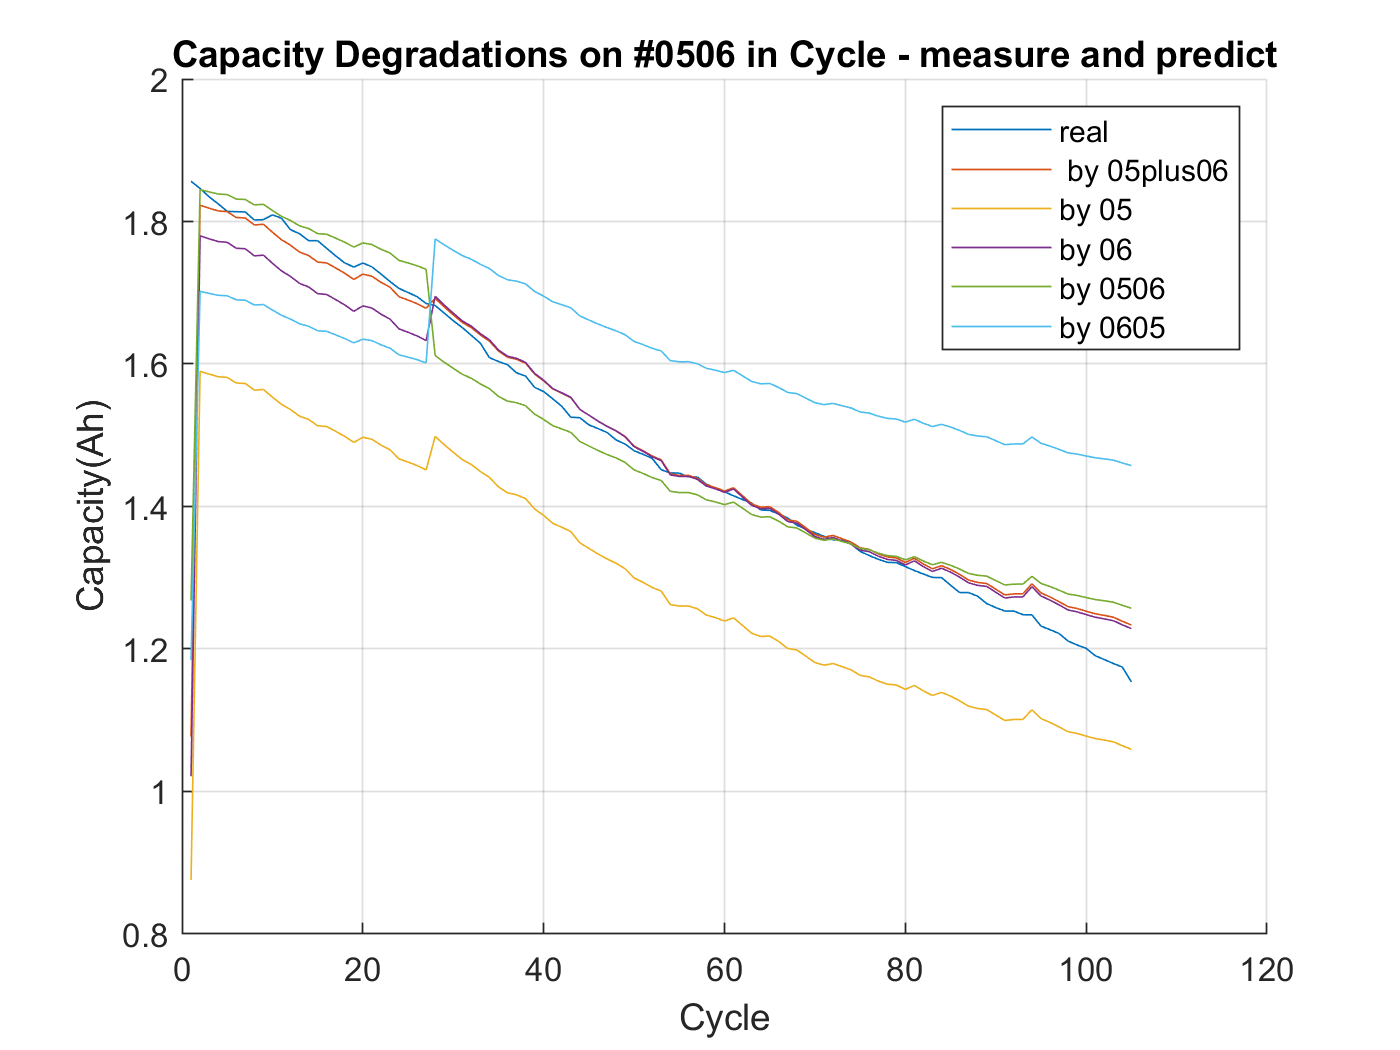


%% plot - hat #56 
figure, hold on,xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations on #0506 in Cycle - measure and predict')
plot(cap_0506), plot(capHat_0506_with_pattern_by_05plus06),plot(capHat_0506_with_pattern_by_05),plot(capHat_0506_with_pattern_by_06),plot(capHat_0506_with_pattern_by_0506),plot(capHat_0506_with_pattern_by_0605),
hold off, grid on, legend('real',' by 05plus06','by 05','by 06','by 0506','by 0605')

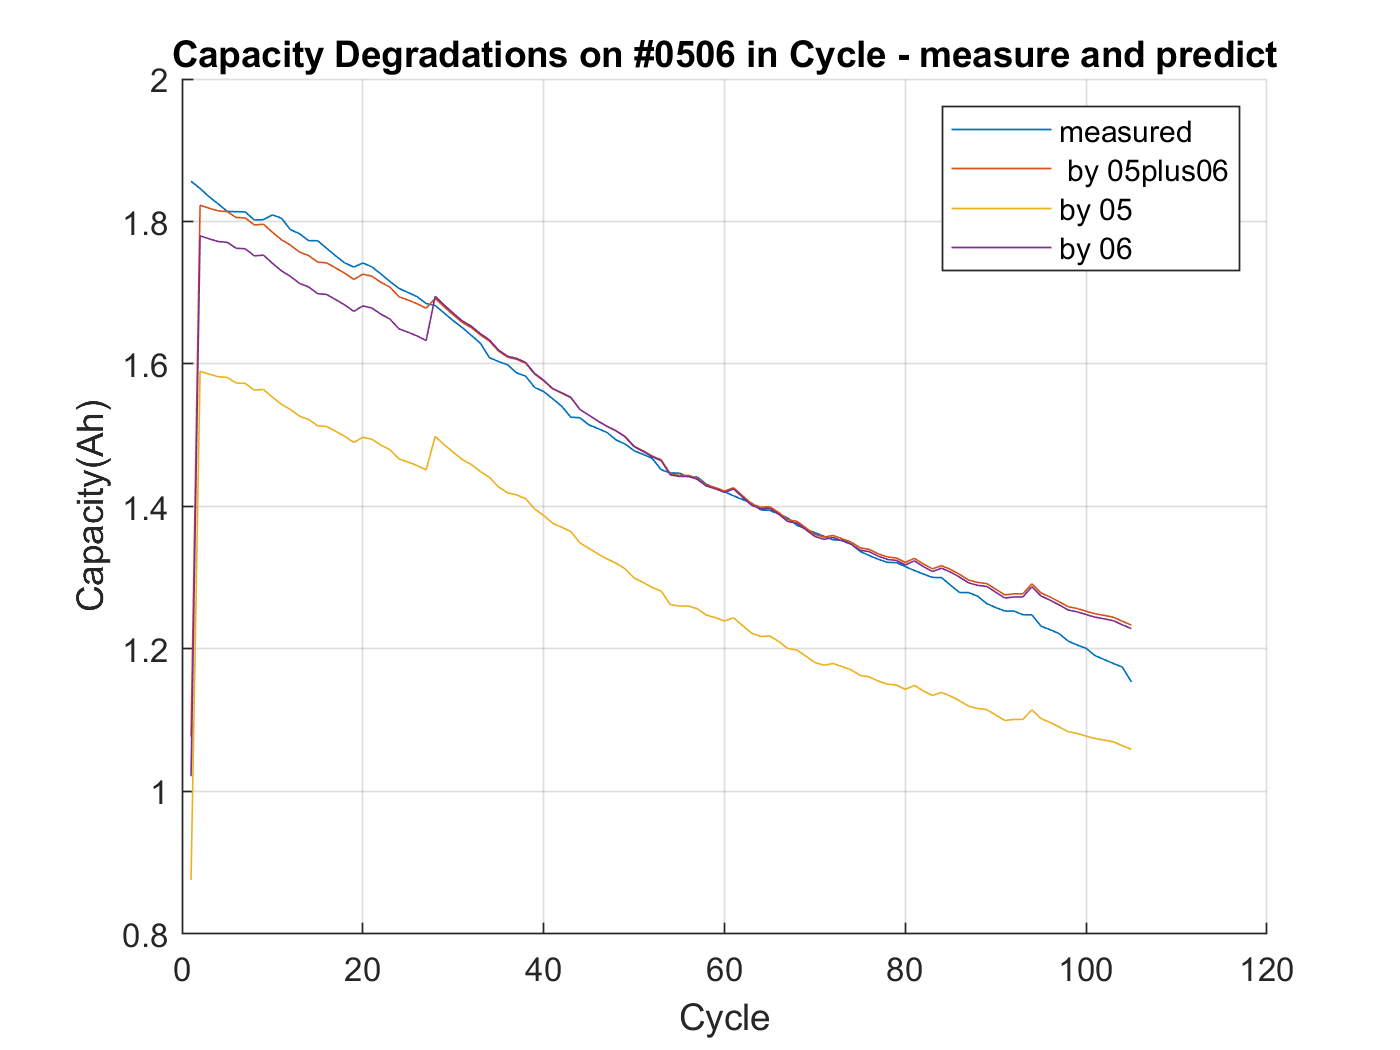

%% plot - hat #56 
figure, hold on,xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations on #0506 in Cycle - measure and predict')
plot(cap_0506), plot(capHat_0506_with_pattern_by_05plus06),plot(capHat_0506_with_pattern_by_05),plot(capHat_0506_with_pattern_by_06)
hold off, grid on, legend('measured',' by 05plus06','by 05','by 06')

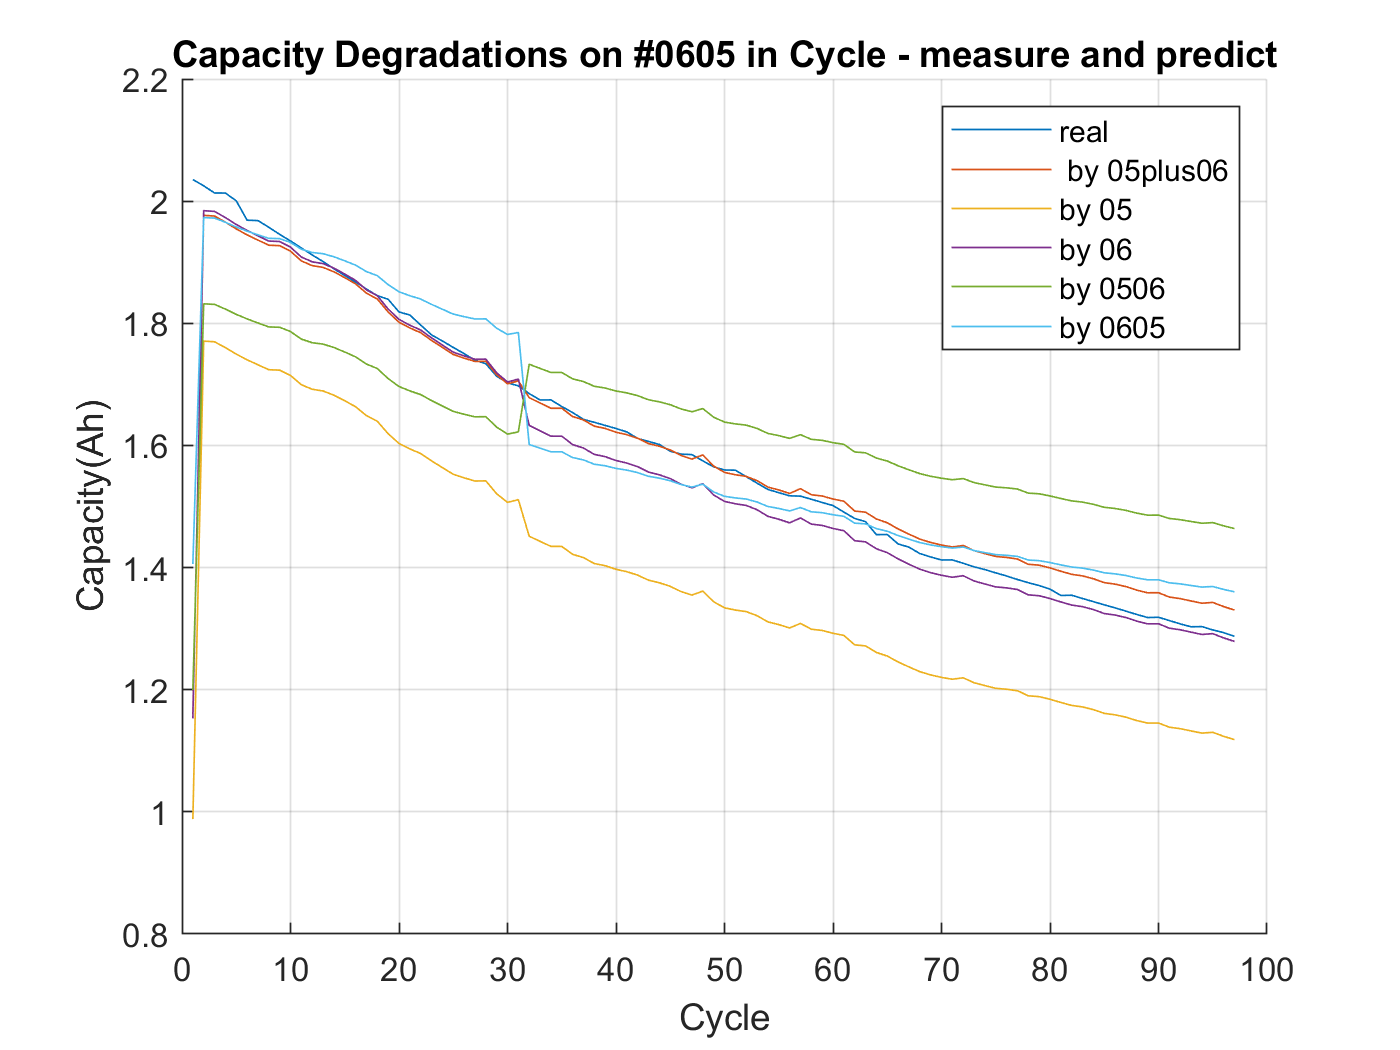



%% plot - hat #65 
figure, hold on,xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations on #0605 in Cycle - measure and predict')
plot(cap_0605), plot(capHat_0605_with_pattern_by_05plus06),plot(capHat_0605_with_pattern_by_05),plot(capHat_0605_with_pattern_by_06),plot(capHat_0605_with_pattern_by_0506),plot(capHat_0605_with_pattern_by_0605),
hold off, grid on, legend('real',' by 05plus06','by 05','by 06','by 0506','by 0605')

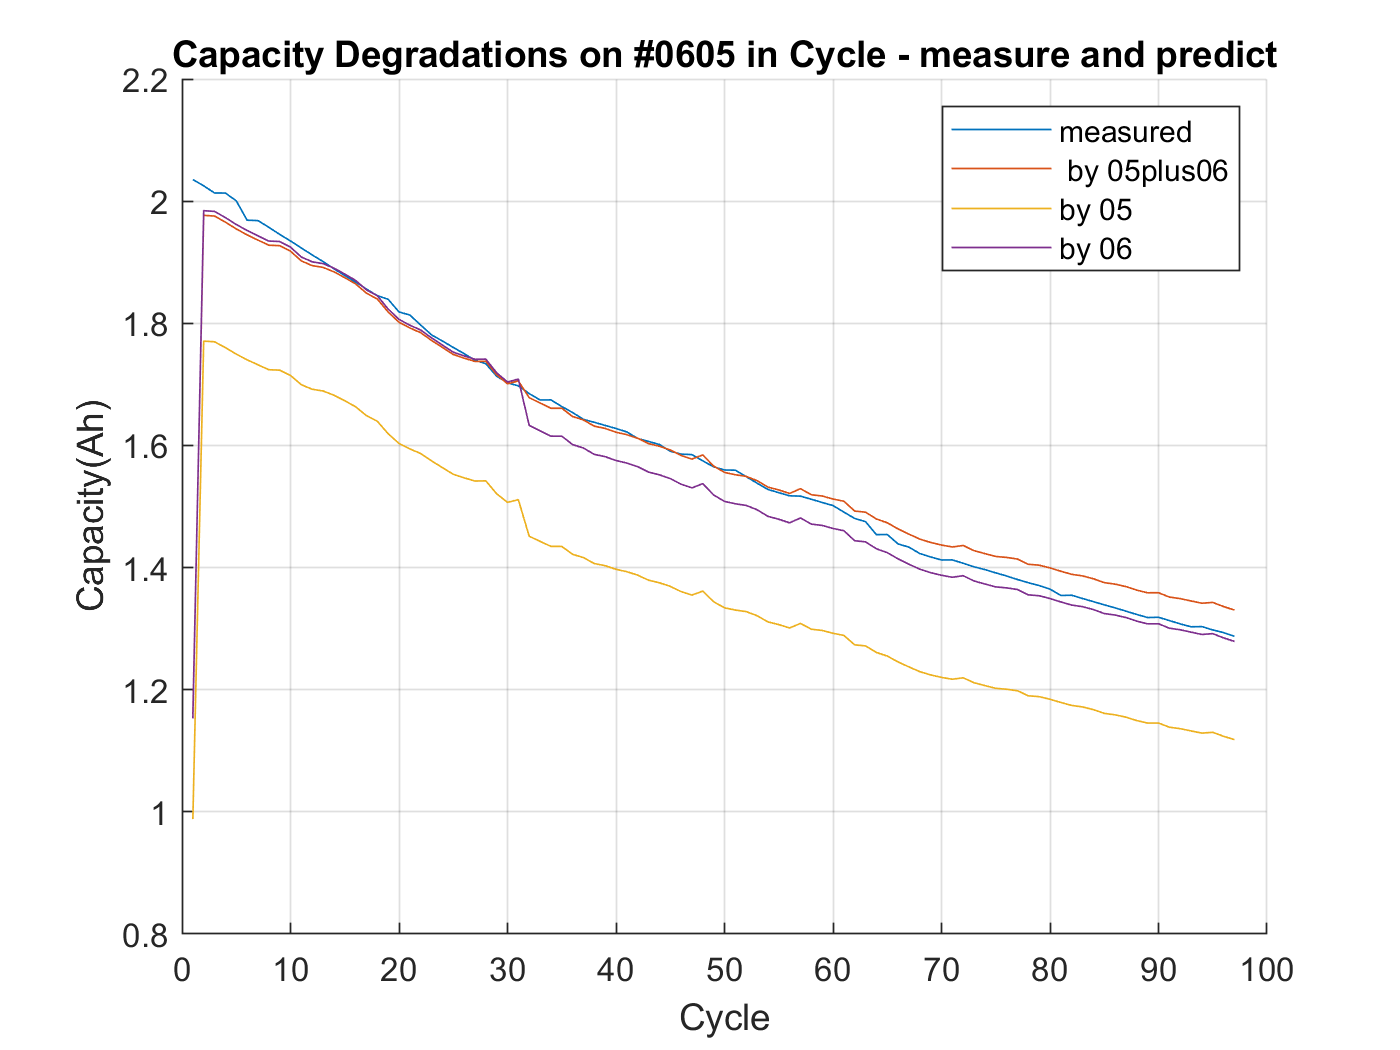

%% plot - hat #65 
figure, hold on,xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations on #0605 in Cycle - measure and predict')
plot(cap_0605), plot(capHat_0605_with_pattern_by_05plus06),plot(capHat_0605_with_pattern_by_05),plot(capHat_0605_with_pattern_by_06)
hold off, grid on, legend('measured',' by 05plus06','by 05','by 06')

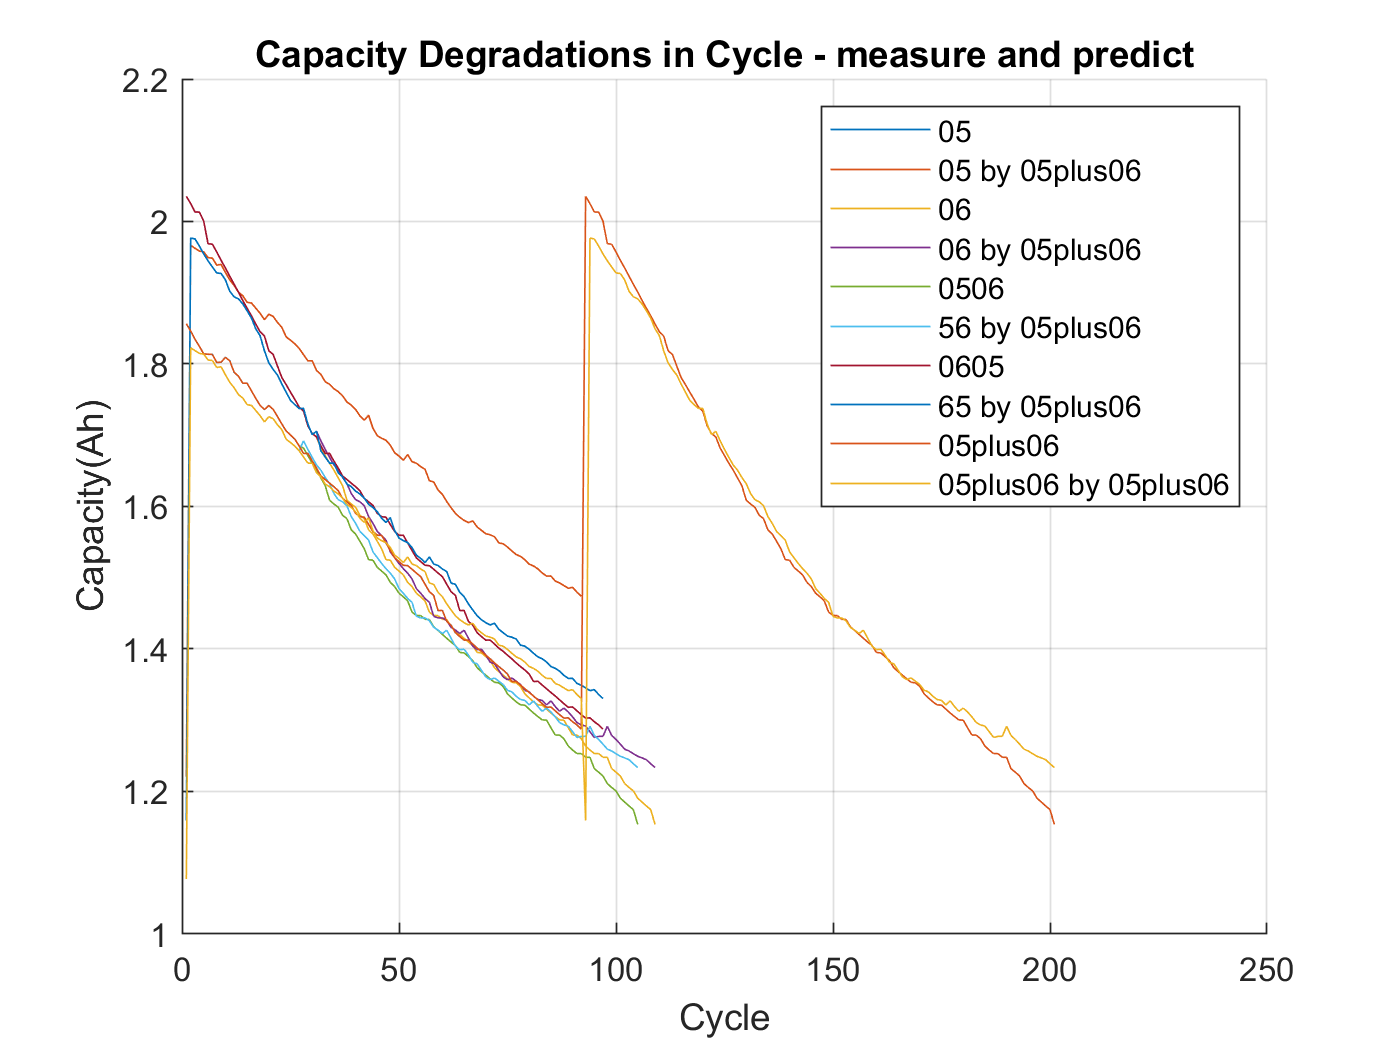

%% plot - hat by All
figure, hold on,xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations in Cycle - measure and predict')
plot(cap_05), plot(capHat_05_with_pattern_by_05plus06)
plot(cap_06), plot(capHat_06_with_pattern_by_05plus06)
plot(cap_0506), plot(capHat_0506_with_pattern_by_05plus06)
plot(cap_0605), plot(capHat_0605_with_pattern_by_05plus06)
plot(cap_05plus06), plot(capHat_05plus06_with_pattern_by_05plus06)

hold off, grid on, legend('05','05 by 05plus06','06','06 by 05plus06','0506','56 by 05plus06','0605','65 by 05plus06','05plus06','05plus06 by 05plus06')

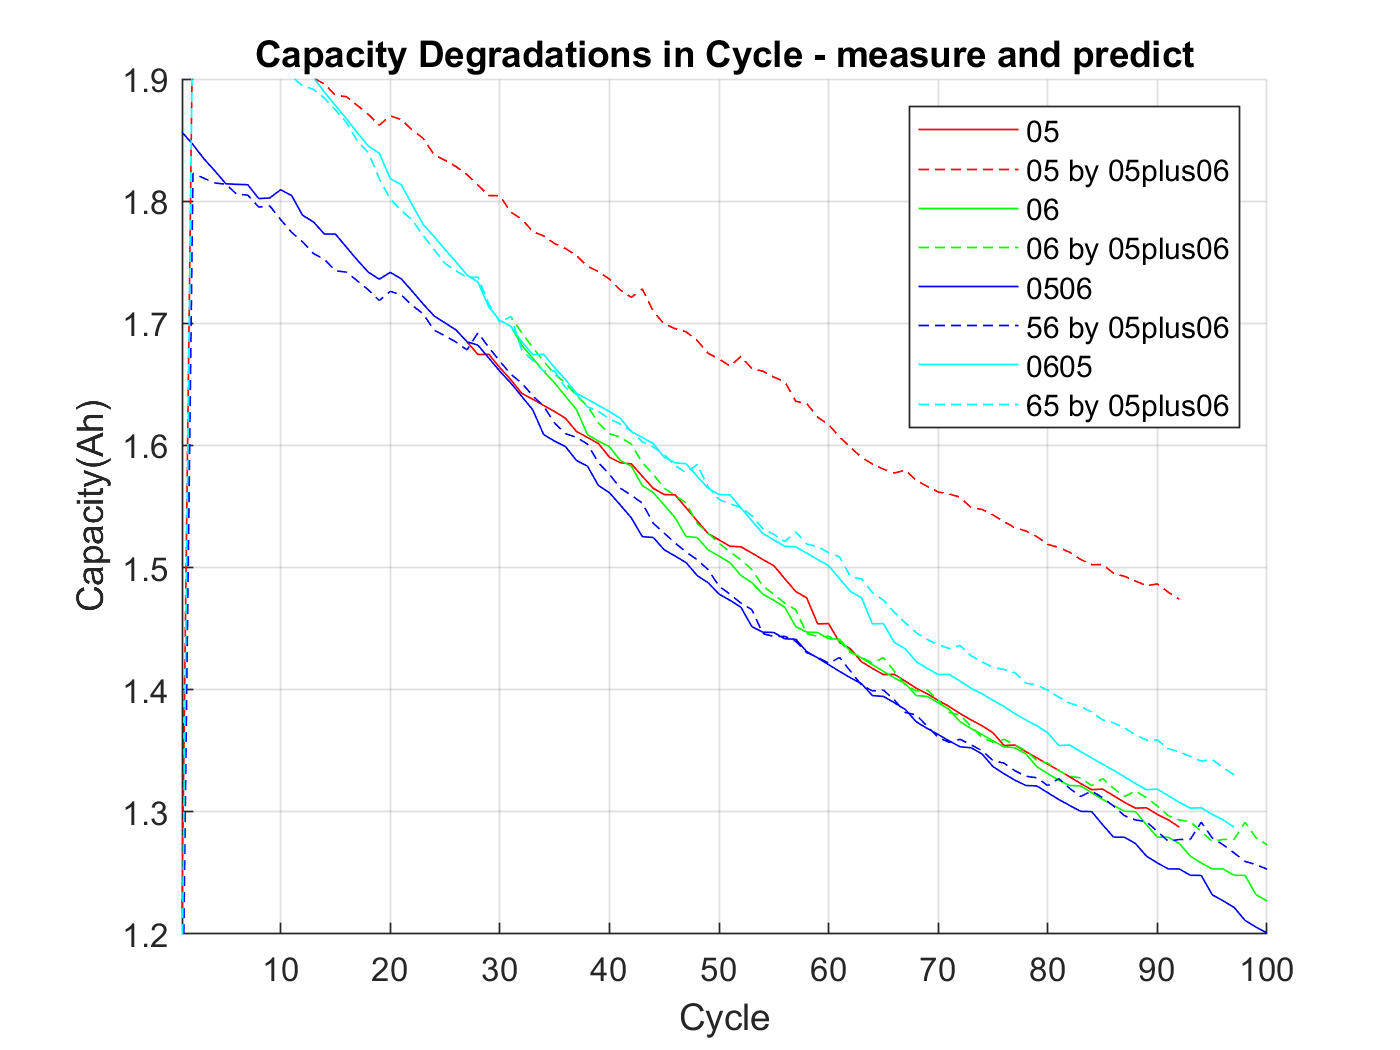


%% plot - hat by All
figure, hold on,xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations in Cycle - measure and predict')
plot(cap_05,'r'), plot(capHat_05_with_pattern_by_05plus06,  'r--')
plot(cap_06,'g'), plot(capHat_06_with_pattern_by_05plus06,  'g--')
plot(cap_0506,'b'), plot(capHat_0506_with_pattern_by_05plus06, 'b--')
plot(cap_0605,'c'), plot(capHat_0605_with_pattern_by_05plus06, 'c--')
ylim([1.2 1.9]), xlim([1,100]),hold off, grid on, legend('05','05 by 05plus06','06','06 by 05plus06','0506','56 by 05plus06','0605','65 by 05plus06')

RMSE

mdl_with_pattern_by_05.RMSE

ans = 0.0851

mdl_with_pattern_by_06.RMSE

ans = 0.0880

mdl_with_pattern_by_0605.RMSE

ans = 0.0808

mdl_with_pattern_by_0506.RMSE

ans = 0.0698

mdl_with_pattern_by_05plus06.RMSE

ans = 0.0867



% https://kr.mathworks.com/matlabcentral/answers/286146-why-rmse-obtained-by-fitlm-in-matlab-does-not-match-with-rmse-calculated-in-excel
% As you can see, dividing by the degrees of freedom is what fitlm must be doing.
% sqrt(sum((y - lm.predict(x)).^2/100)) 
% sqrt(sum((y - lm.predict(x)).^2/100))  -> dividing by the degrees of freedom
RMSE_05_by_05 = sqrt(mean(( cap_05' - capHat_05_with_pattern_by_05 ).^2))

RMSE_05_by_05 = 0.0842

RMSE_06_by_06 = sqrt(mean(( cap_06' - capHat_06_with_pattern_by_06 ).^2))

RMSE_06_by_06 = 0.0872

RMSE_0506_by_05 = sqrt(mean(( cap_0506' - capHat_0506_with_pattern_by_05 ).^2))

RMSE_0506_by_05 = 0.2111

RMSE_0506_by_06 = sqrt(mean(( cap_0506' - capHat_0506_with_pattern_by_06 ).^2))

RMSE_0506_by_06 = 0.0890

RMSE_0506_by_05plus06 = sqrt(mean(( cap_0506' - capHat_0506_with_pattern_by_05plus06 ).^2))

RMSE_0506_by_05plus06 = 0.0795

RMSE_0605_by_05 = sqrt(mean(( cap_0605' - capHat_0605_with_pattern_by_05 ).^2))

RMSE_0605_by_05 = 0.2317

RMSE_0605_by_06 = sqrt(mean(( cap_0605' - capHat_0605_with_pattern_by_06 ).^2))

RMSE_0605_by_06 = 0.0946

RMSE_0605_by_05plus06 = sqrt(mean(( cap_0605' - capHat_0605_with_pattern_by_05plus06 ).^2))

RMSE_0605_by_05plus06 = 0.0921

%result_05_06_patten_change = [27 31];
%result_06_05_patten_change = [30 27];
idx_0506_change = 28; % last + 1
idx_0605_change = 31;

RMSE_0506_by_05 = sqrt(mean(( cap_0506(idx_0506_change:end)' - capHat_0506_with_pattern_by_05(idx_0506_change:end) ).^2))

RMSE_0506_by_05 = 0.1662

RMSE_0506_by_06 = sqrt(mean(( cap_0506(idx_0506_change:end)' - capHat_0506_with_pattern_by_06(idx_0506_change:end) ).^2))

RMSE_0506_by_06 = 0.0232

RMSE_0506_by_05plus06 = sqrt(mean(( cap_0506(idx_0506_change:end)' - capHat_0506_with_pattern_by_05plus06(idx_0506_change:end) ).^2))

RMSE_0506_by_05plus06 = 0.0252

RMSE_0605_by_05 = sqrt(mean(( cap_0605(idx_0605_change:end)' - capHat_0605_with_pattern_by_05(idx_0605_change:end) ).^2))

RMSE_0605_by_05 = 0.2021

RMSE_0605_by_06 = sqrt(mean(( cap_0605(idx_0605_change:end)' - capHat_0605_with_pattern_by_06(idx_0605_change:end) ).^2))

RMSE_0605_by_06 = 0.0348

RMSE_0605_by_05plus06 = sqrt(mean(( cap_0605(idx_0605_change:end)' - capHat_0605_with_pattern_by_05plus06(idx_0605_change:end) ).^2))

RMSE_0605_by_05plus06 = 0.0249